### Exercise 1 Thies book problem(one piezometer)

### Apply the Theis model to a classic case with one piezometer, estimating T and S, data from 'Fetter_Example.xlsx'.

clear; clc; close all;
set(0, 'DefaultFigureColor', 'k');          
set(0, 'DefaultAxesFontSize', 12);
set(0, 'DefaultAxesFontWeight', 'bold');   
set(0, 'DefaultLineLineWidth', 1.5);        
set(0, 'DefaultLineMarkerSize', 6);        

t_min = [3, 5, 8, 12, 20, 24, 30, 38, 47, 50, 60, 70, 80, 90, 100, ...
         130, 160, 200, 260, 320, 380, 500];
s_ft = [0.3, 0.7, 1.3, 2.1, 3.2, 3.6, 4.1, 4.7, 5.1, 5.3, 5.7, 6.1, ...
        6.3, 6.7, 7.0, 7.5, 8.3, 8.5, 9.2, 9.7, 10.2, 10.9];
Q_gal = 220;    
r_ft = 824;       

ft_to_m = 0.3048;
min_to_day = 1/1440;
gal_to_m3 = 0.00378541;

t_d = t_min * min_to_day;          
s_m = s_ft * ft_to_m;              
r_m = r_ft * ft_to_m;             
Q_m3d = Q_gal * gal_to_m3 * 1440;  

fprintf('  Q = %.2f m³/d\n  r = %.2f m\n', Q_m3d, r_m);

  Q = 1199.22 m³/d
  r = 251.16 m


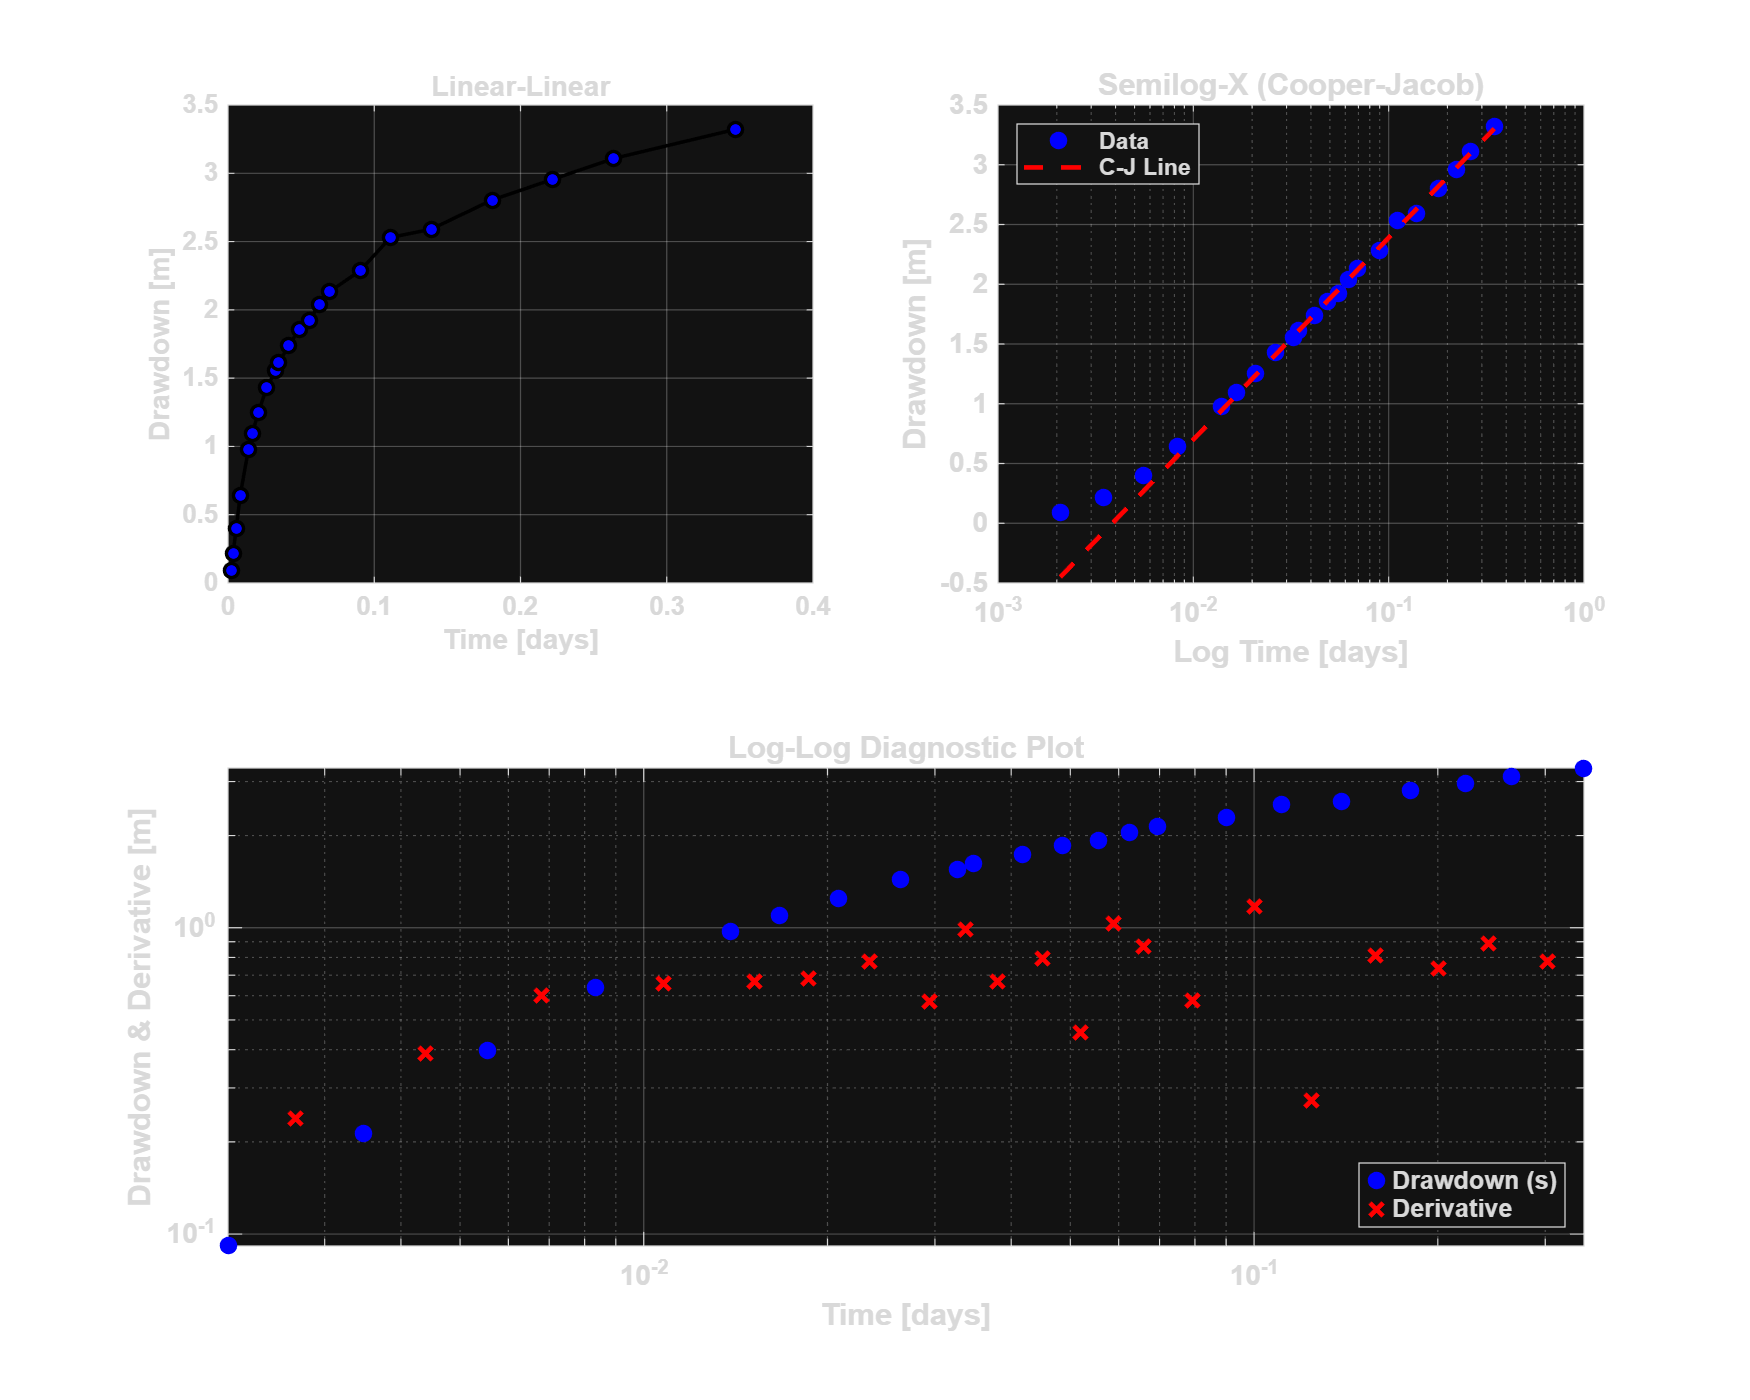

ds = diff(s_m);
d_lnt = diff(log(t_d)); 
deriv = ds ./ d_lnt;
t_mid = exp((log(t_d(1:end-1)) + log(t_d(2:end))) / 2);

figure('Name', 'Dimensional Analysis', 'Position', [100, 100, 1000, 800]);
subplot(2, 2, 1);%linear
plot(t_d, s_m, 'o-', 'Color', 'k', 'MarkerFaceColor', 'b'); 
xlabel('Time [days]'); ylabel('Drawdown [m]');
title('Linear-Linear');
grid on; box on;

subplot(2, 2, 2);%semilog
semilogx(t_d, s_m, 'bo', 'MarkerFaceColor', 'b');
hold on;
xlabel('Log Time [days]'); ylabel('Drawdown [m]');
title('Semilog-X (Cooper-Jacob)');
grid on; box on;

subplot(2, 2, [3, 4]); %loglog
loglog(t_d, s_m, 'bo', 'MarkerFaceColor', 'b', 'DisplayName', 'Drawdown (s)');
hold on;
loglog(t_mid, deriv, 'rx', 'LineWidth', 2, 'MarkerSize', 8, 'DisplayName', 'Derivative');
xlabel('Time [days]'); ylabel('Drawdown & Derivative [m]');
title('Log-Log Diagnostic Plot');
legend('Location', 'southeast');
grid on; grid minor; box on;
axis tight;

idx_cj = (length(t_d)-7) : length(t_d); %CJ
t_cj = t_d(idx_cj);
s_cj = s_m(idx_cj);

p = polyfit(log10(t_cj), s_cj, 1);%s = m*log10(t) + c
slope_m = p(1);
intercept_c = p(2);
T_cj = (2.3 * Q_m3d) / (4 * pi * slope_m);
t0 = 10^(-intercept_c / slope_m);
S_cj = (2.25 * T_cj * t0) / r_m^2;

subplot(2, 2, 2); 
s_cj_line = polyval(p, log10(t_d));
semilogx(t_d, s_cj_line, 'r--', 'LineWidth', 2, 'DisplayName', 'C-J Fit');
legend('Data','C-J Line', 'Location', 'northwest', 'FontSize', 10);

- Interval of radial flow :

Based on the diagnostic plot, the derivative curve stabilizes to a constant value relatively early in the test, visual inspection of the semilog plot confirms that the data follows a straight line starting from approximately **30-40 minutes**.

However, the strict theoretical criterion for the Cooper-Jacob approximation (*u*<0.01) suggests a starting time of **386 minutes**(the code and calculation results are below, after residual plot). This discrepancy occurs because the visual linear trend appears as soon as u<0.1, while the mathematical calculation enforces a strict error margin of <0.25%.

For the purpose of this analysis, we consider the **interval of radial flow to begin around 30-40 minutes**, satisfying the engineering tolerance u<0.1.

- Early-time behavior(Well effects):

 There is **no evidence of wellbore storage effects** observed in the early-time data.

In the log-log diagnostic plot, the derivative curve does not exhibit the characteristic straight line with a slope of 1 that indicates wellbore storage. This is physically consistent with the experimental setup: the observation well is located at a significant distance (r=251m)  from the pumping well. At such distances, wellbore storage effects from the pumping well are typically attenuated and do not influence the drawdown observed in the piezometer. The data appears to follow the Theis curve from the very first measurements.

- Late-time behavior(Possible boundaries):

The data shows **no indication of boundary effects** (neither impermeable barriers nor recharge boundaries) within the 500-minute duration of the test.

**Diagnostic Plot:** The derivative curve remains stable and horizontal during the late time, without trending upward (which would indicate a no-flow boundary) or dropping towards zero (which would indicate a constant-head boundary).

**Semilog Plot:** The drawdown data continues to follow a straight line perfectly until the end of the test.**Conclusion:** The aquifer behaves as an **infinite-acting system** within the radius of influence generated during this pumping period.

theis_model = @(P, t) (Q_m3d / (4 * pi * P(1))) .* expint((r_m^2 * P(2)) ./ (4 * P(1) .* t));
obj_fun = @(P) sum((s_m - theis_model(P, t_d)).^2); % SSE
initial_guess = [T_cj, S_cj]; 
best_params = fminsearch(obj_fun, initial_guess, optimset('Display', 'off'));
T_opt = best_params(1);
S_opt = best_params(2);
fprintf('\nresults \n')


results 


fprintf('%-20s %-15s %-15s\n', 'Method', 'T (m2/d)', 'S (-)');

Method               T (m2/d)        S (-)          


fprintf('%-20s %-15.4f %-15.2e\n', 'Cooper-Jacob', T_cj, S_cj);

Cooper-Jacob         129.9607        1.78e-05       


fprintf('%-20s %-15.4f %-15.2e\n', 'Theis', T_opt, S_opt);

Theis                123.0583        2.09e-05       



% error analysis (the relative percentage difference between CJ and thies)
% formula: ((CJ - Theis) / Theis)* 100
error_T = abs((T_cj - T_opt) / T_opt) * 100;
error_S = abs((S_cj - S_opt) / S_opt) * 100;
fprintf('\nError analysis\n');


Error analysis


fprintf('Relative difference in Transmissivity (T): %.2f%%\n', error_T);

Relative difference in Transmissivity (T): 5.61%


fprintf('Relative difference in Storativity (S):    %.2f%%\n', error_S);

Relative difference in Storativity (S):    14.81%



% consistency check
if error_T < 10 && error_S < 20
    fprintf('Conclusion: results are highly consistent.\n');
elseif error_T < 20
    fprintf('Conclusion: results are reasonably consistent.\n');
else
    fprintf('Conclusion: significant discrepancy observed,check late-time data selection.\n');
end

Conclusion: results are highly consistent.



% goodness of fit statistics and residual plot
s_model_at_data = theis_model([T_opt, S_opt], t_d); % theoretical drawdown at EXACT data points (not smooth t)
residuals = s_m - s_model_at_data; % residuals 
sse = sum(residuals.^2); % sum of squared errors
n = length(s_m);
rmse = sqrt(sse / n); % RMSE (root mean square error)
s_mean = mean(s_m);
sst = sum((s_m - s_mean).^2); 
r_squared = 1 - (sse / sst); % R-squared
fprintf('\ngoodness of fit statistic\n');


goodness of fit statistic


fprintf('RMSE (Root Mean Square Error): %.4f m\n', rmse);

RMSE (Root Mean Square Error): 0.0277 m


fprintf('R-squared (Determination Coeff): %.4f\n', r_squared);

R-squared (Determination Coeff): 0.9991


fprintf('SSE (Sum of Squared Errors):     %.4f\n', sse);

SSE (Sum of Squared Errors):     0.0169


if r_squared > 0.98
    fprintf('Assessment: Excellent fit.\n');
elseif r_squared > 0.90
    fprintf('Assessment: Good fit.\n');
else
    fprintf('Assessment: Poor fit. Check model validity.\n');
end

Assessment: Excellent fit.


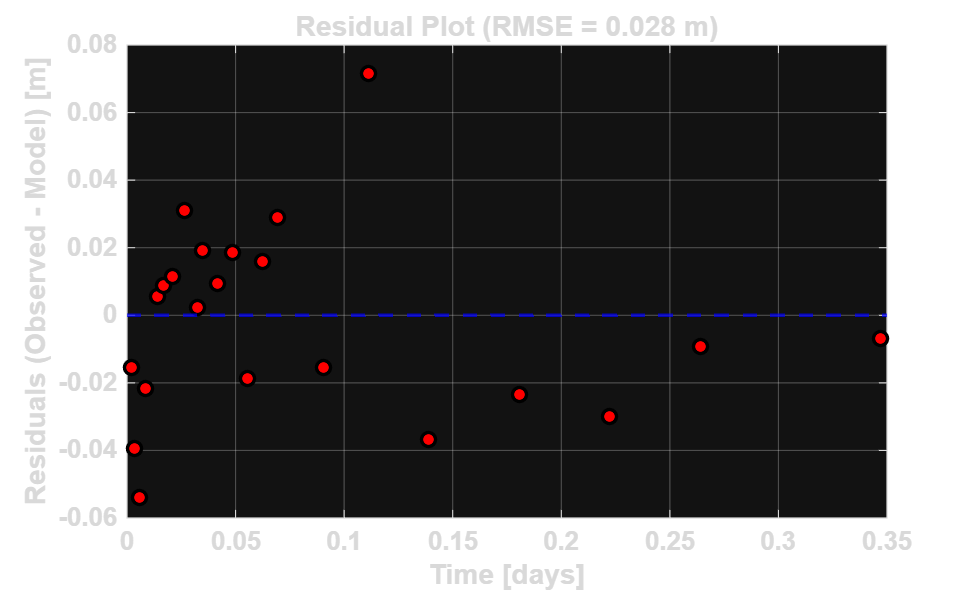


% residual plot
figure('Name', 'Residual Analysis');
plot(t_d, residuals, 'ko', 'MarkerFaceColor', 'r', 'MarkerSize', 6);
hold on;
yline(0, 'b--', 'LineWidth', 1.5); % Zero line
xlabel('Time [days]'); 
ylabel('Residuals (Observed - Model) [m]');
title(sprintf('Residual Plot (RMSE = %.3f m)', rmse));
grid on; box on;


% start of radial flow
u_limit = 0.01; % Criterion: radial flow is valid when u < 0.01
t_start_radial = (r_m^2 * S_opt) / (4 * T_opt * u_limit);
fprintf('\n Interval of radial flow \n');


 Interval of radial flow 


fprintf('Radial flow starts approximately at t > %.2f days (%.1f mins)\n', ...
        t_start_radial, t_start_radial * 1440);

Radial flow starts approximately at t > 0.27 days (386.6 mins)


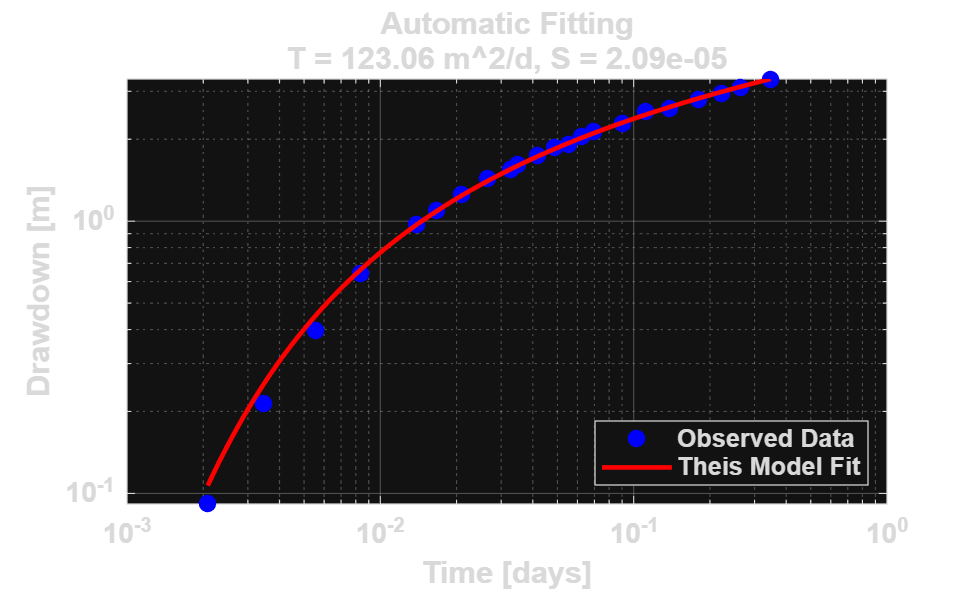

t_smooth = logspace(log10(min(t_d)), log10(max(t_d)), 100);
s_fitted = theis_model([T_opt, S_opt], t_smooth);

figure('Name', 'Theis Verification'); 
loglog(t_d, s_m, 'bo', 'MarkerFaceColor', 'b', 'DisplayName', 'Observed Data');
hold on;
loglog(t_smooth, s_fitted, 'r-', 'LineWidth', 2, 'DisplayName', 'Theis Model Fit');

xlabel('Time [days]'); ylabel('Drawdown [m]');
title(sprintf('Automatic Fitting\nT = %.2f m^2/d, S = %.2e', T_opt, S_opt));
legend('Location', 'southeast');
grid on; grid minor; box on;

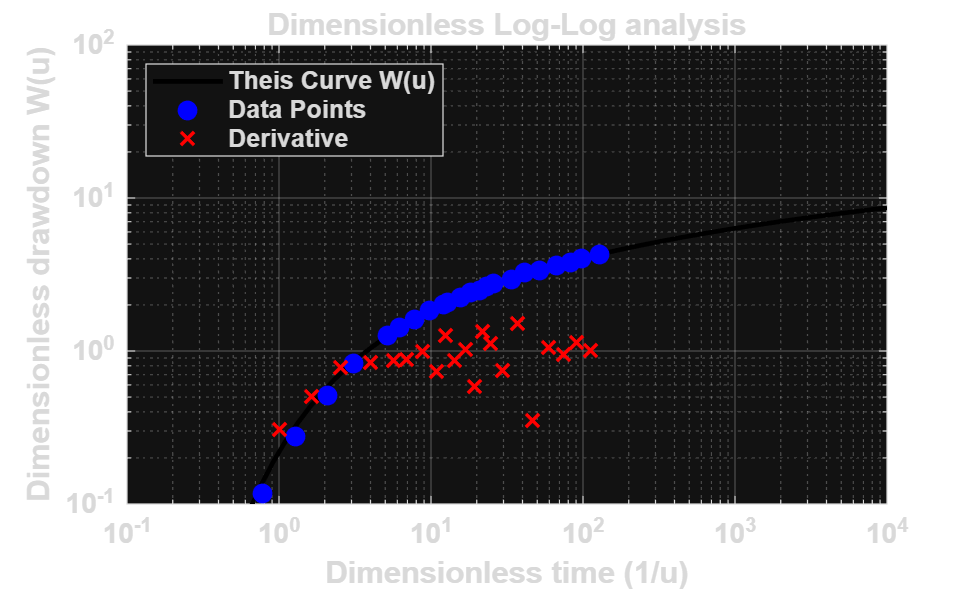


%dimensionless
one_over_u = (4 * T_opt .* t_d) ./ (r_m^2 * S_opt);
W_u_data = (4 * pi * T_opt .* s_m) / Q_m3d; 
dW = diff(W_u_data);
dln_u = diff(log(one_over_u));
W_deriv = dW ./ dln_u;
u_mid = exp((log(one_over_u(1:end-1)) + log(one_over_u(2:end))) / 2);
% Theoretical theis curve
u_theory = logspace(-4, 4, 100); 
inv_u_theory = 1./u_theory;
W_theory = expint(u_theory);
figure('Name', 'Dimensionless plot'); 

loglog(inv_u_theory, W_theory, 'k-', 'LineWidth', 2, 'DisplayName', 'Theis Curve W(u)');
hold on;
loglog(one_over_u, W_u_data, 'bo', 'MarkerFaceColor', 'b', 'MarkerSize', 7, 'DisplayName', 'Data Points'); % data points
loglog(u_mid, W_deriv, 'rx', 'MarkerSize', 8, 'DisplayName', 'Derivative'); % derivative

xlabel('Dimensionless time (1/u)');
ylabel('Dimensionless drawdown W(u)');
title('Dimensionless Log-Log analysis');
legend('Location', 'northwest');
grid on; grid minor; box on;
axis([1e-1 1e4 1e-1 1e2]); 

## Result and interpretation

#### Diagnostic Plots (based on the curves and the derivative):

**Behavior Observed:**The log-log diagnostic plot shows that the derivative curve stabilizes and becomes horizontal (constant value) after the initial period. This indicates the establishment of **infinite-acting radial flow**, which is the fundamental assumption of the Theis model.

#### **Consistency analysis:**

**Comparison of Methods:**The Transmissivity (*T*) and Storativity (*S*) values obtained from the **Cooper-Jacob approximation** are very close to those obtained from the **Automatic Fitting (Theis)**. The difference between Copper&Jacob and Thies method in transmissivity and storativity is 5.61% 14.81%, respectively. The RMSE, R-Squared and SSE between thes two methods are 0.0277m, 0,9991,0.0169 ,respectively, which means the two methods have high consistency.

**Conclusion:**The high consistency between the two methods and the excellent fit of the data to the theoretical Theis curve confirm that the aquifer behaves as an **ideal, homogeneous, and isotropic confined aquifer**.

## Exercise 2 Test with two piezometers

Analyze a pumping test with two piezometers at different distances, using the Theis model, the Cooper–Jacob approximation and automatic fitting model, comparing parameters and behavior between both points.

%clear; clc; close all;
set(0, 'DefaultFigureColor', 'w');
set(0, 'DefaultAxesFontSize', 11);
set(0, 'DefaultAxesFontWeight', 'bold');
set(0, 'DefaultLineLineWidth', 1.5);
set(0, 'DefaultLineMarkerSize', 6);
Q_m3d = 788;  % m3/d

wells(1).path = 'C:\Users\kaya1\OneDrive\Desktop\Test30.txt';
wells(1).r = 30;
wells(1).name = 'P30 (r=30m)';

wells(2).path = 'C:\Users\kaya1\OneDrive\Desktop\Test90.txt';
wells(2).r = 90;
wells(2).name = 'P90 (r=90m)';
results = []; 
for i = 1:length(wells)
    try
        raw = readmatrix(wells(i).path, 'FileType', 'text');
    catch
        raw = load(wells(i).path, '-ascii'); 
    end
    valid_idx = (raw(:,1) > 1e-10) & (raw(:,2) > 1e-10);
    clean_data = raw(valid_idx, :);
   
    wells(i).t = clean_data(:,1); 
    wells(i).s = clean_data(:,2);
    
    fprintf('   %s: %d valid points.\n', wells(i).name, length(wells(i).t));
end

   P30 (r=30m): 34 valid points.
   P90 (r=90m): 35 valid points.



--- Analyzing P30 (r=30m) ---


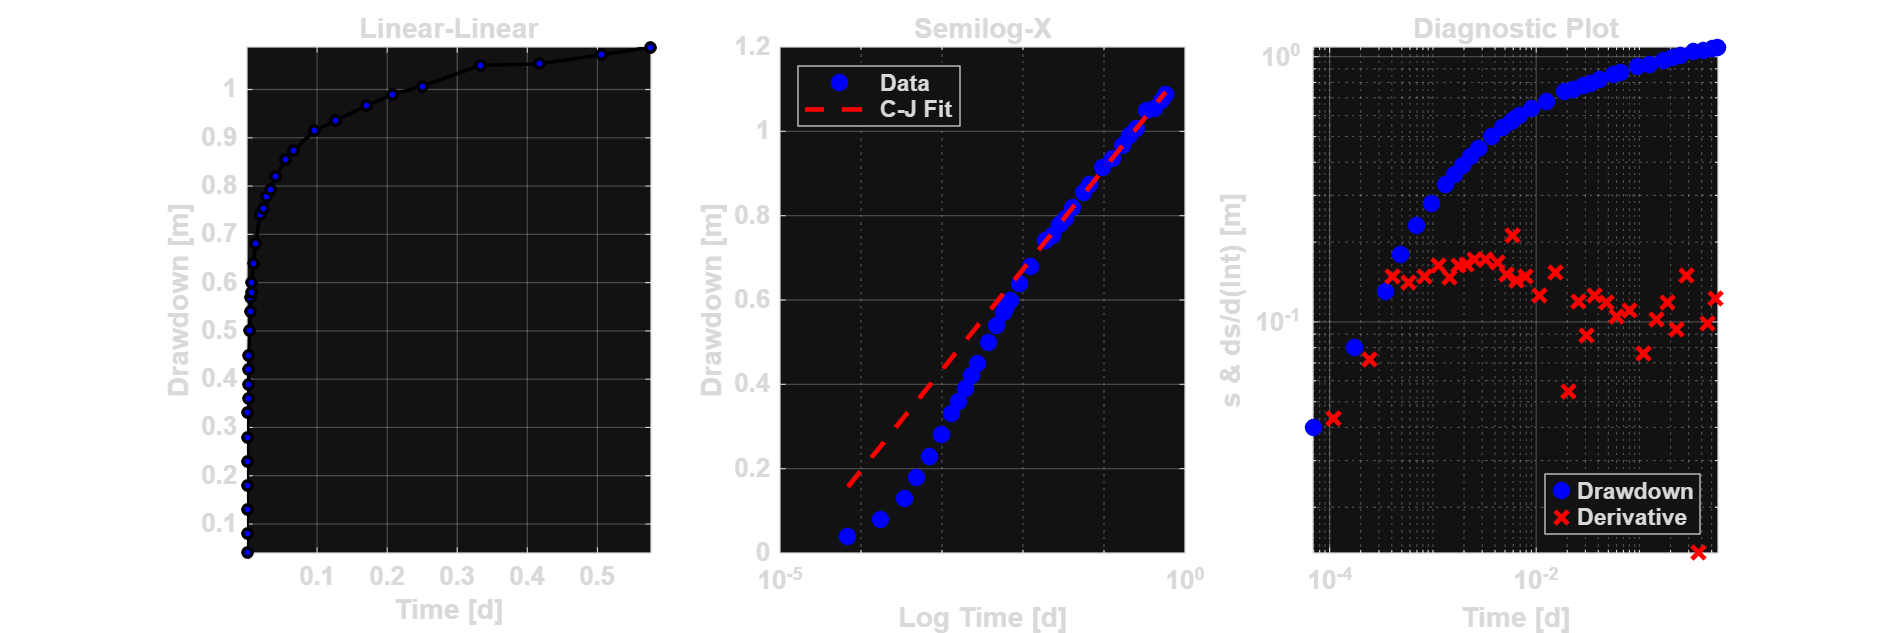

  Cooper-Jacob: T = 605.11, S = 2.29e-05


  Auto-Fitting: T = 480.49, S = 1.12e-04



--- Analyzing P90 (r=90m) ---


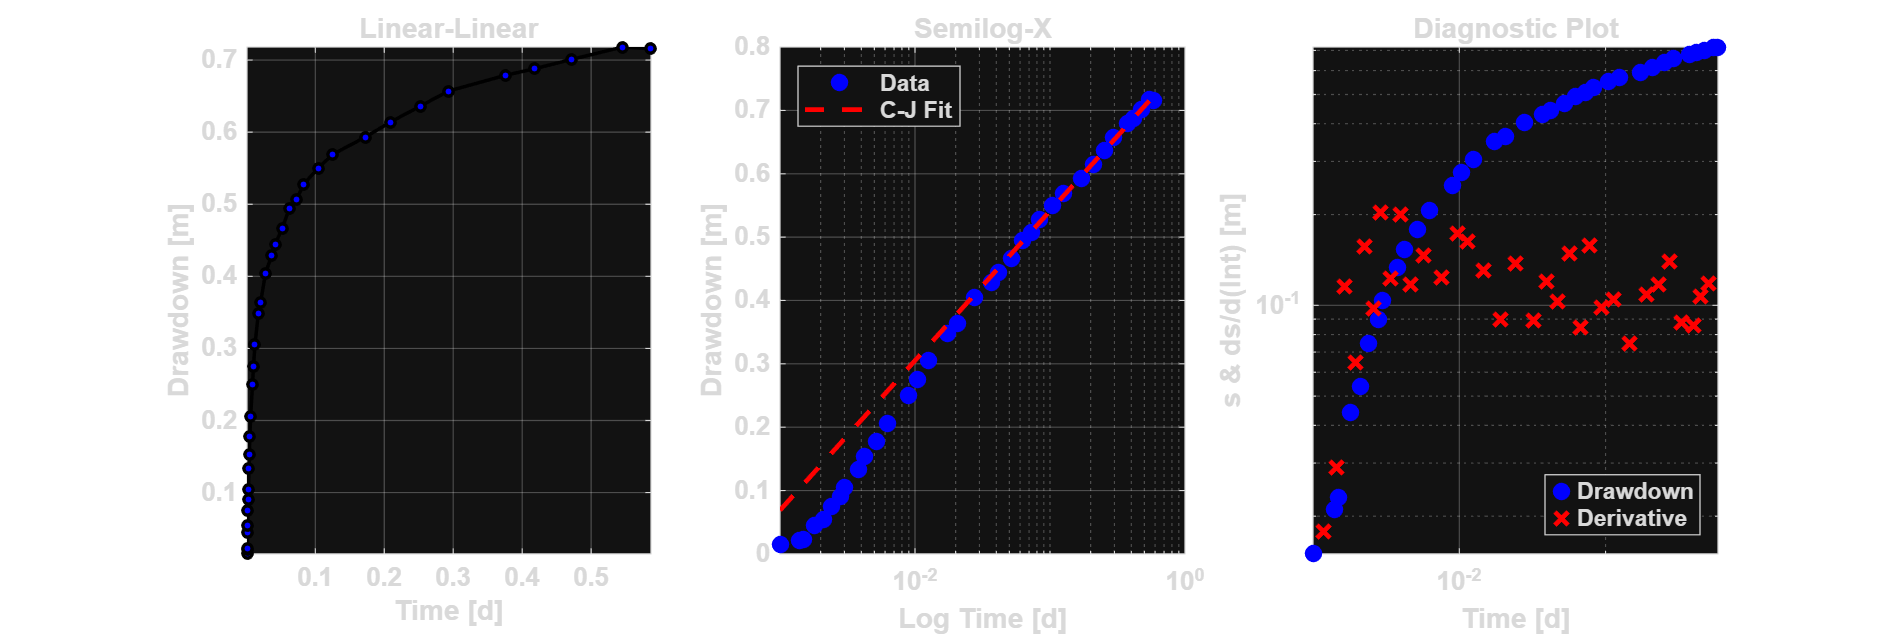

  Cooper-Jacob: T = 611.18, S = 8.68e-05


  Auto-Fitting: T = 501.31, S = 2.03e-04



%dimension
for i = 1:length(wells)
    fprintf('\n--- Analyzing %s ---\n', wells(i).name);
    t = wells(i).t; s = wells(i).s; r = wells(i).r;
    ds = diff(s);
    d_lnt = diff(log(t));
    deriv = ds ./ d_lnt;
    t_mid = exp((log(t(1:end-1)) + log(t(2:end))) / 2);
    figure('Name', [wells(i).name ' - Analysis'], 'Position', [50+(i-1)*50, 100, 1200, 400]);
   
    subplot(1, 3, 1);%linear
    plot(t, s, 'ko-', 'MarkerFaceColor', 'b', 'MarkerSize', 4);
    xlabel('Time [d]'); ylabel('Drawdown [m]'); title('Linear-Linear');
    grid on; axis tight;

    subplot(1, 3, 2);%semilog
    semilogx(t, s, 'bo', 'MarkerFaceColor', 'b'); hold on;
    xlabel('Log Time [d]'); ylabel('Drawdown [m]'); title('Semilog-X');
    grid on;
    
    subplot(1, 3, 3);%loglog
    loglog(t, s, 'bo', 'MarkerFaceColor', 'b', 'DisplayName', 'Drawdown'); hold on;
    loglog(t_mid, deriv, 'rx', 'MarkerSize', 8, 'LineWidth', 2, 'DisplayName', 'Derivative');
    xlabel('Time [d]'); ylabel('s & ds/d(lnt) [m]'); title('Diagnostic Plot');
    legend('Location', 'southeast'); grid on; axis tight;

    idx_cj = round(length(t)*0.6) : length(t);%CJ/40%
    p = polyfit(log10(t(idx_cj)), s(idx_cj), 1);
    
    T_cj = (2.303 * Q_m3d) / (4 * pi * p(1));
    S_cj = (2.25 * T_cj * 10^(-p(2)/p(1))) / r^2;
    subplot(1, 3, 2);
    semilogx(t, polyval(p, log10(t)), 'r--', 'LineWidth', 2, 'DisplayName', 'C-J Fit');
    legend('Data', 'C-J Fit', 'Location', 'northwest');
    
    theis_fun = @(P,t_val) (Q_m3d/(4*pi*P(1))) * expint((r^2*P(2))./(4*P(1)*t_val));%theis
    obj_fun = @(P) sum((s - theis_fun(P, t)).^2);
    
    opt_params = fminsearch(obj_fun, [T_cj, S_cj]);
    
    results(i).T_cj = T_cj;       % Cooper-Jacob T
    results(i).S_cj = S_cj;       % Cooper-Jacob S
    results(i).T_opt = opt_params(1); % Auto-Fit T
    results(i).S_opt = opt_params(2); % Auto-Fit S
    
    fprintf('  Cooper-Jacob: T = %.2f, S = %.2e\n', T_cj, S_cj);
    fprintf('  Auto-Fitting: T = %.2f, S = %.2e\n', results(i).T_opt, results(i).S_opt);
end


%dimensionless
fprintf('\nDimensionless analysis\n');


Dimensionless analysis


u_th = logspace(-5, 2, 100);
inv_u_th = 1./u_th;
W_th = expint(u_th);
figure('Name', 'Dimensionless Analysis (Combined)', 'Position', [150, 500, 700, 500]);

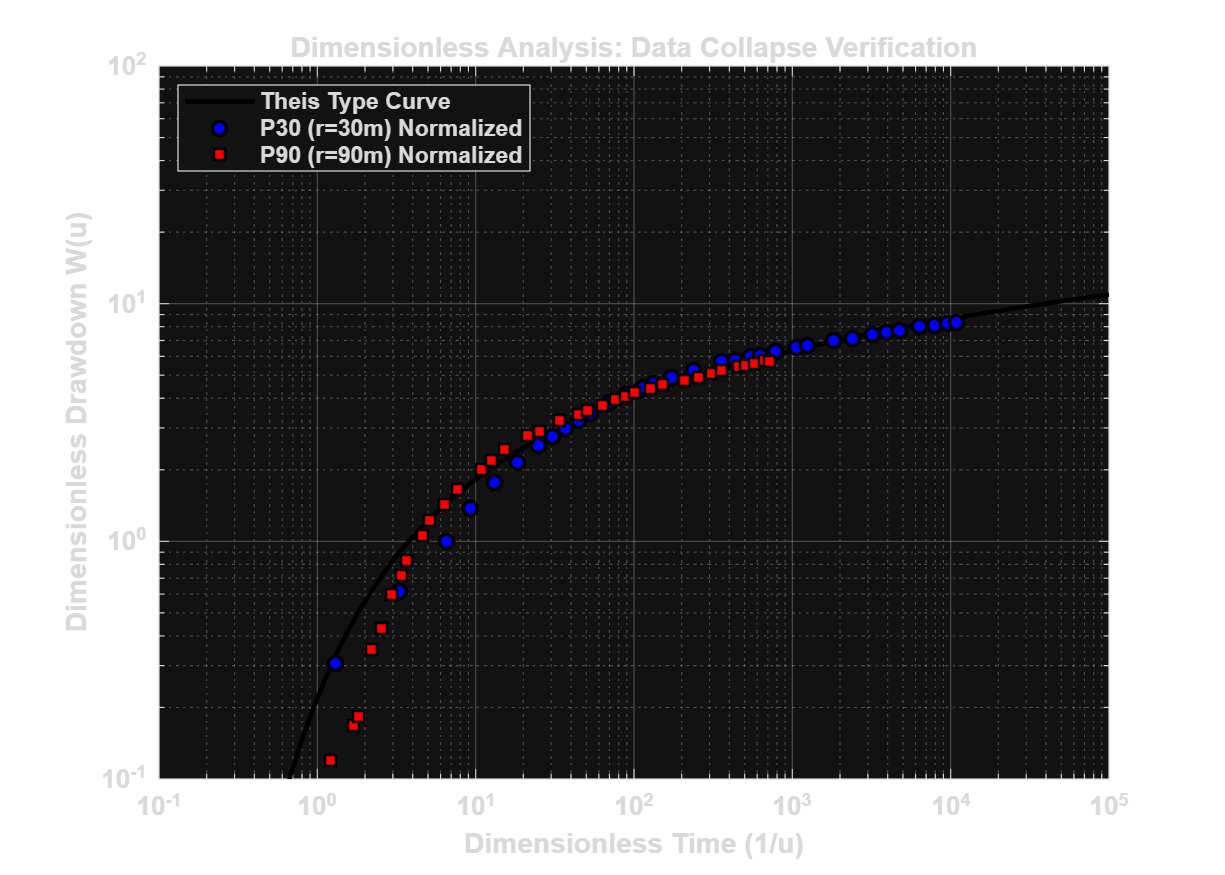

loglog(inv_u_th, W_th, 'k-', 'LineWidth', 2, 'DisplayName', 'Theis Type Curve');
hold on;

colors = {'b', 'r'}; markers = {'o', 's'};

for i = 1:length(wells)
    t = wells(i).t; s = wells(i).s; r = wells(i).r;
    T = results(i).T_opt; S = results(i).S_opt;
    inv_u_data = (4 * T * t) ./ (r^2 * S);
    W_data = (4 * pi * T * s) / Q_m3d;
    
    loglog(inv_u_data, W_data, 'LineStyle', 'none', ...
        'Marker', markers{i}, 'MarkerFaceColor', colors{i}, 'Color', 'k', ...
        'DisplayName', sprintf('%s Normalized', wells(i).name));
end

xlabel('Dimensionless Time (1/u)'); ylabel('Dimensionless Drawdown W(u)');
title('Dimensionless Analysis: Data Collapse Verification');
legend('Location', 'northwest'); grid on; axis([1e-1 1e5 1e-1 100]);

%analysis
fprintf('\ncomparative table: T & S estimation \n');


comparative table: T & S estimation 


fprintf(' %-15s  %-15s  %-12s  %-12s \n', 'Piezometer', 'Method', 'T (m²/d)', 'S (-)');

 Piezometer       Method           T (m²/d)      S (-)        


for i = 1:length(wells)
    % Row 1: Cooper-Jacob
    fprintf(' %-15s  %-15s  %-12.2f  %-12.2e \n', ...
        wells(i).name, 'Cooper-Jacob', results(i).T_cj, results(i).S_cj);
    % Row 2: Auto-Fitting
    fprintf(' %-15s  %-15s  %-12.2f  %-12.2e \n', ...
        '', 'Auto-Fitting', results(i).T_opt, results(i).S_opt);
end

 P30 (r=30m)      Cooper-Jacob     605.11        2.29e-05     


                  Auto-Fitting     480.49        1.12e-04     


 P90 (r=90m)      Cooper-Jacob     611.18        8.68e-05     


                  Auto-Fitting     501.31        2.03e-04     


% Consistency Check Calculation
diff_T = abs(results(1).T_opt - results(2).T_opt) / mean([results(1).T_opt, results(2).T_opt]) * 100;
fprintf('\nConsistency check results \n');


Consistency check results 


fprintf('Relative percentage difference in T between P30 and P90: %.2f%%\n', diff_T);

Relative percentage difference in T between P30 and P90: 4.24%


% Interpretation based on standard engineering tolerance
if diff_T < 5
    fprintf('Conclusion: Excellent consistency. The aquifer appears highly homogeneous.\n');
elseif diff_T < 10
    fprintf('Conclusion: Good consistency. The results are reliable.\n');
elseif diff_T < 20
    fprintf('Conclusion: Acceptable consistency. Slight heterogeneity may exist.\n');
else
    fprintf('Conclusion: Significant discrepancy (>20%%).\n');
    fprintf('            Possible causes: Aquifer heterogeneity, boundary effects, or data errors.\n');
end

Conclusion: Excellent consistency. The aquifer appears highly homogeneous.


**Assessment of Theis-type behavior:**

**1. Curve matching (Goodness of fit):**

The dimensionless plots demonstrate a **high degree of conformity** between the field data and the theoretical Theis type curve. For both Piezometer 1 (r=30m) and Piezometer 2  (r=90m), the normalized drawdown data points W(u) vs 1/u**collapse** efficiently onto the standard Theis curve. This indicates that the computed parameters (T and S) accurately describe the aquifer system.

**2. Derivative analysis:**

The normalized derivative points align well with the theoretical Theis derivative curve. Crucially, in the late-time region (large 1/u), the derivative stabilizes to a horizontal trend (constant value), which is the signature of **Infinite Acting Radial Flow (IARF)**. There is no evidence of double-porosity behavior (no characteristic "dip" in the derivative).

**3. Boundary effects:**

The data follows the Theis curve until the end of the test duration. There are **no significant deviations** in the late time:

No upward trend (which would indicate a no-flow boundary).

No downward trend (which would indicate a constant-head boundary or leakage).

**Conclusion:**

Based on the excellent visual fit and the stabilization of the diagnostic derivative, it is concluded that the aquifer response **strongly resembles a Theis-type behavior**, representing a homogeneous, isotropic, and effectively infinite confined aquifer.

## Exercise 3 Pumping tests at UNAL

This includes: pumping, recovery and step-drawdown tests at the UNAL well, with piezometers at different depths.

%clear; clc; close all; 
filename = 'C:\Users\kaya1\OneDrive\Desktop\Recovery_Processed.txt';      
Q_Ls = 2.2;                     
r = 9.4;                        
t_p_hours = 49;               

Q = Q_Ls * 0.001 * 86400;       
t_p = t_p_hours * 60;           
t_p_day = t_p / 1440;           

if ~isfile(filename), error(['找不到文件: ' filename]); end
data = readmatrix(filename);

t_prime = data(:,1); 
s_prime = data(:,2);
valid = t_prime > 0 & s_prime > 0;
t_prime = t_prime(valid);
s_prime = s_prime(valid);
t_prime_day = t_prime / 1440;


t_total = t_p + t_prime; 
t_ratio = t_total ./ t_prime; 
t_ag_day = (t_p_day .* t_prime_day) ./ (t_p_day + t_prime_day); 

%dimesion
idx_start = floor(0.3 * length(t_ag_day));
idx_end = floor(0.8 * length(t_ag_day));
if idx_start < 1, idx_start = 1; end

x_fit = log10(t_ag_day(idx_start:idx_end));
y_fit = s_prime(idx_start:idx_end);
p = polyfit(x_fit, y_fit, 1);
B = p(1); A = p(2);

T_rec = (2.303 * Q) / (4 * pi * abs(B));
theis_W = @(u) expint(u);
superpos_func = @(p, t_pr_d) (Q / (4*pi*p(1))) * ...
    (theis_W((r^2 * p(2)) ./ (4 * p(1) * (t_p_day + t_pr_d))) - ...
     theis_W((r^2 * p(2)) ./ (4 * p(1) * t_pr_d)));

cost_func = @(p) sum((s_prime - superpos_func(p, t_prime_day)).^2);
x0 = [abs(T_rec), 1e-4];
options = optimset('Display', 'off', 'TolX', 1e-8);
try
    p_opt = fminsearch(cost_func, x0, options);
    T_opt = p_opt(1);
    S_opt = p_opt(2); 
catch
    T_opt = T_rec; S_opt = 1e-4;
end
s_model = superpos_func([T_opt, S_opt], t_prime_day);

ds_dln_tag = zeros(size(s_prime));%derivative
log_tag = log(t_ag_day);
ds_dln_tag(2:end-1) = (s_prime(3:end) - s_prime(1:end-2)) ./ (log_tag(3:end) - log_tag(1:end-2));
ds_dln_tag(1) = ds_dln_tag(2); ds_dln_tag(end) = ds_dln_tag(end-1);
ds_dln_tag = smoothdata(ds_dln_tag, 'movmean', 5);
fprintf('recovery test analysis\n');

recovery test analysis


fprintf('linear T = %.4f m^2/day \n', T_rec);

linear T = 8.6094 m^2/day 


fprintf('Auto Fitting   T = %.4f m^2/day\n', T_opt);

Auto Fitting   T = 8.6816 m^2/day


fprintf('[auto fitting  S = %.4e \n', S_opt);

[auto fitting  S = 1.2974e-01 


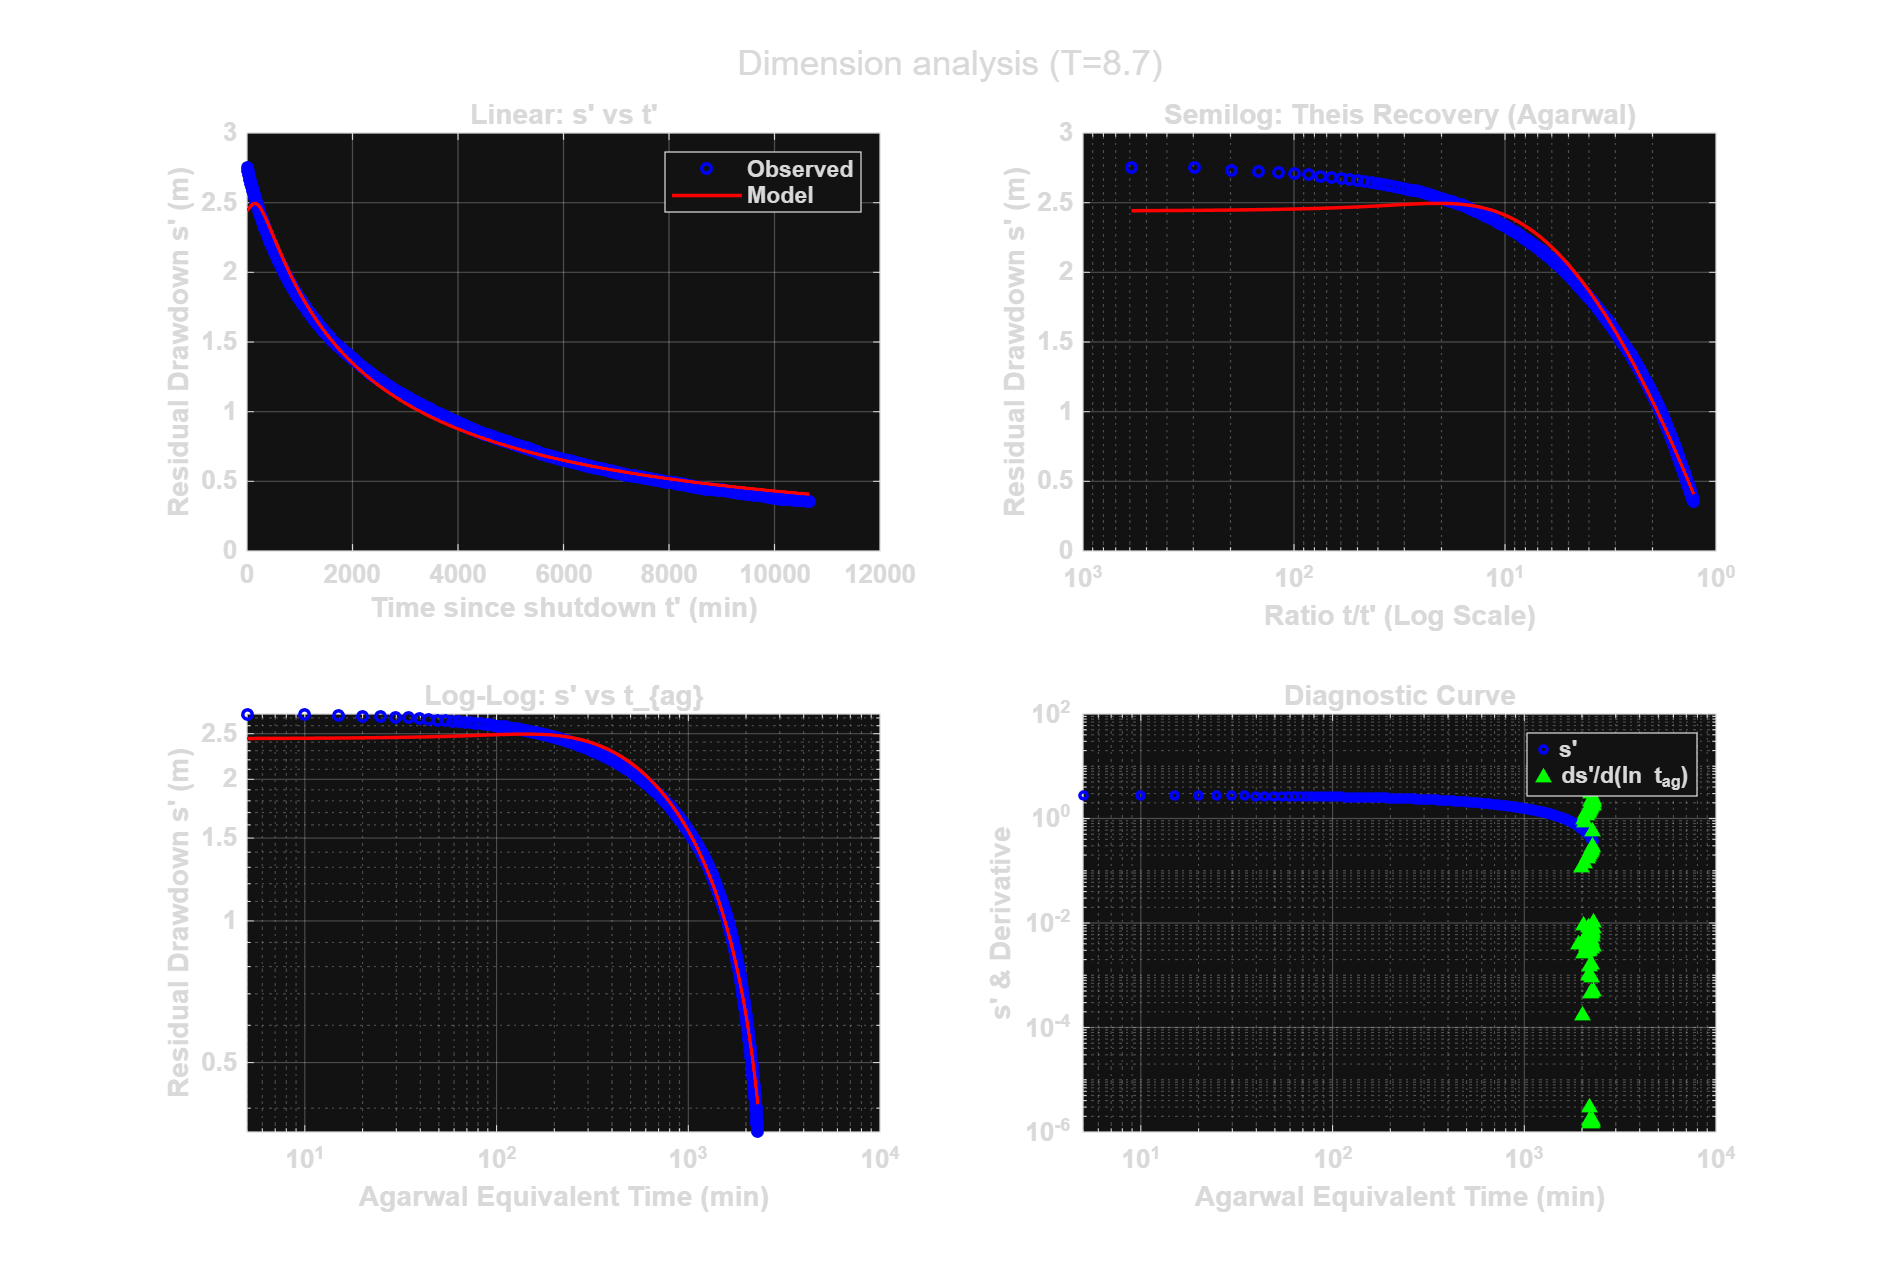

%dimensionless
inv_u_D = (4 * T_opt * t_ag_day) ./ (S_opt * r^2);
s_D = (4 * pi * T_opt * s_prime) ./ Q;
der_s_D = ds_dln_tag * (4 * pi * T_opt / Q);

u_th = logspace(-5, 2, 100);%theory theis 
inv_u_th = 1./u_th;
W_th = expint(u_th);
der_W_th = exp(-u_th);

figure('Name', 'Recovery - Dimensional', 'Color', 'w', 'Position', [50 50 1200 800]);
sgtitle(['Dimension analysis (T=' num2str(T_opt,'%.1f') ')']);
subplot(2,2,1);%linear 
plot(t_prime, s_prime, 'bo', 'MarkerSize', 4); hold on;
plot(t_prime, s_model, 'r-', 'LineWidth', 1.5);
xlabel('Time since shutdown t'' (min)'); ylabel('Residual Drawdown s'' (m)');
title('Linear: s'' vs t'''); grid on; legend('Observed', 'Model');

subplot(2,2,2);%semilog
semilogx(t_ratio, s_prime, 'bo', 'MarkerSize', 4); hold on;
x_line = logspace(log10(min(t_ratio)), log10(max(t_ratio)), 100);
semilogx(t_ratio, s_model, 'r-'); 
set(gca, 'XDir', 'reverse'); 
xlabel('Ratio t/t'' (Log Scale)'); ylabel('Residual Drawdown s'' (m)');
title('Semilog: Theis Recovery (Agarwal)'); grid on; 

subplot(2,2,3);%loglog
loglog(t_ag_day*1440, s_prime, 'bo', 'MarkerSize', 4); hold on;
loglog(t_ag_day*1440, s_model, 'r-', 'LineWidth', 1.5);
xlabel('Agarwal Equivalent Time (min)'); ylabel('Residual Drawdown s'' (m)');
title('Log-Log: s'' vs t_{ag}'); grid on;

subplot(2,2,4);
loglog(t_ag_day*1440, s_prime, 'bo', 'MarkerSize', 3); hold on;
pos_idx = ds_dln_tag > 0;
loglog(t_ag_day(pos_idx)*1440, ds_dln_tag(pos_idx), 'g^', 'MarkerFaceColor', 'g', 'MarkerSize', 4);
xlabel('Agarwal Equivalent Time (min)'); ylabel('s'' & Derivative');
title('Diagnostic Curve'); grid on; legend('s''', 'ds''/d(ln t_{ag})');

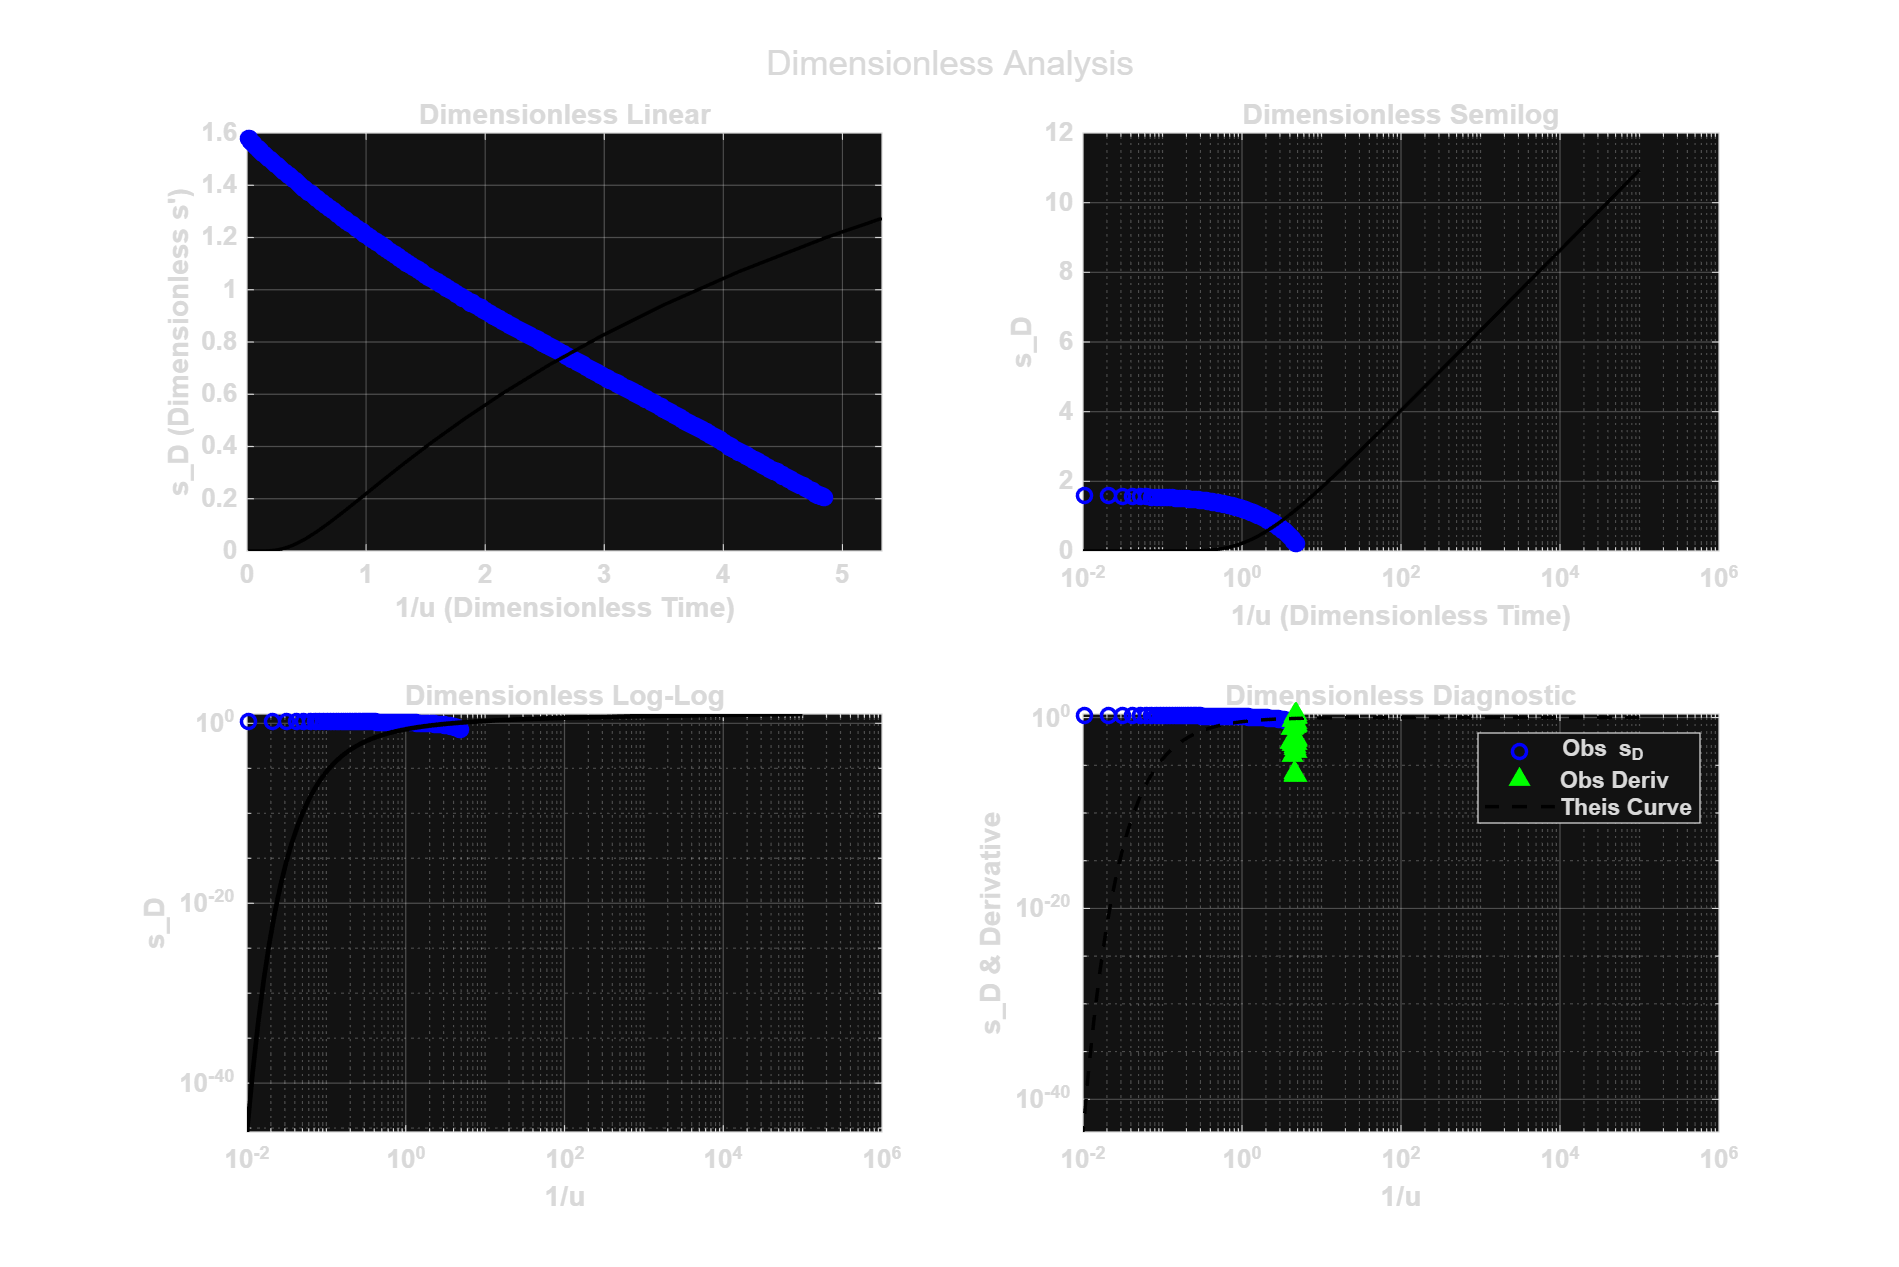

%dimensionless
figure('Name', 'Recovery - Dimensionless', 'Color', 'w', 'Position', [100 100 1200 800]);
sgtitle('Dimensionless Analysis');

subplot(2,2,1);%linear
plot(inv_u_D, s_D, 'bo'); hold on;
plot(inv_u_th, W_th, 'k-');
xlabel('1/u (Dimensionless Time)'); ylabel('s_D (Dimensionless s'')');
title('Dimensionless Linear'); grid on; xlim([0 max(inv_u_D)*1.1]);

subplot(2,2,2);%semilog
semilogx(inv_u_D, s_D, 'bo'); hold on;
semilogx(inv_u_th, W_th, 'k-');
xlabel('1/u (Dimensionless Time)'); ylabel('s_D');
title('Dimensionless Semilog'); grid on;

subplot(2,2,3);%loglog
loglog(inv_u_D, s_D, 'bo'); hold on;
loglog(inv_u_th, W_th, 'k-', 'LineWidth', 2);
xlabel('1/u'); ylabel('s_D');
title('Dimensionless Log-Log'); grid on;

subplot(2,2,4);%diagnostic
loglog(inv_u_D, s_D, 'bo'); hold on;
if any(pos_idx)
    loglog(inv_u_D(pos_idx), der_s_D(pos_idx), 'g^', 'MarkerFaceColor', 'g');
end
loglog(inv_u_th, der_W_th, 'k--', 'LineWidth', 1.5);
xlabel('1/u'); ylabel('s_D & Derivative');
title('Dimensionless Diagnostic'); grid on;
legend('Obs s_D', 'Obs Deriv', 'Theis Curve', 'Theis Deriv');


%step test
%clear; clc; close all;
filename = 'Step_Processed.txt';%Hantush-Bierschenk method
Q_steps_Ls = [0.5, 1.4, 2.2]; 
Durations = [100, 100, 680]; %duration
Q_steps = Q_steps_Ls * 0.001 * 86400; %m^3/day
fprintf('flow rate (m^3/day): %.2f, %.2f, %.2f\n', Q_steps);

flow rate (m^3/day): 43.20, 120.96, 190.08


if ~isfile(filename), error(['找不到文件: ' filename]); end
data = readmatrix(filename);
t_total = data(:,1); 
s_total = data(:,2); 

num_steps = length(Q_steps);
s_end = zeros(1, num_steps); 
step_indices = cell(1, num_steps); 

current_time = 0;
for i = 1:num_steps
    start_t = current_time;
    end_t = current_time + Durations(i);
    
    idx = t_total > start_t & t_total <= end_t;
    step_indices{i} = idx;
    s_segment = s_total(idx);
    if ~isempty(s_segment)
        s_end(i) = mean(s_segment(end-4:end)); 
    else
        error(['check time', i]);
    end
    
    current_time = end_t;
end

fprintf('drawdown at the end of each step(m): %.2f, %.2f, %.2f\n', s_end);

drawdown at the end of each step(m): -0.06, 2.50, 28.21


% Jacob: s_w = B * Q + C * Q^2
% linear: s_w / Q = B + C * Q
% Y = s_w / Q, X = Q.  
sw_Q = s_end ./ Q_steps; % Specific Drawdown

p = polyfit(Q_steps, sw_Q, 1);
C = p(1); % Non-linear well loss coefficient
B = p(2); % Linear aquifer loss coefficient

fprintf('\nresult\n');


result


fprintf('equation: s_w = %.4f * Q + %.4e * Q^2\n', B, C);

equation: s_w = -0.0626 * Q + 1.0041e-03 * Q^2


fprintf('B = %.4f day/m^2\n', B);

B = -0.0626 day/m^2


fprintf('C = %.4e day^2/m^5\n', C);

C = 1.0041e-03 day^2/m^5


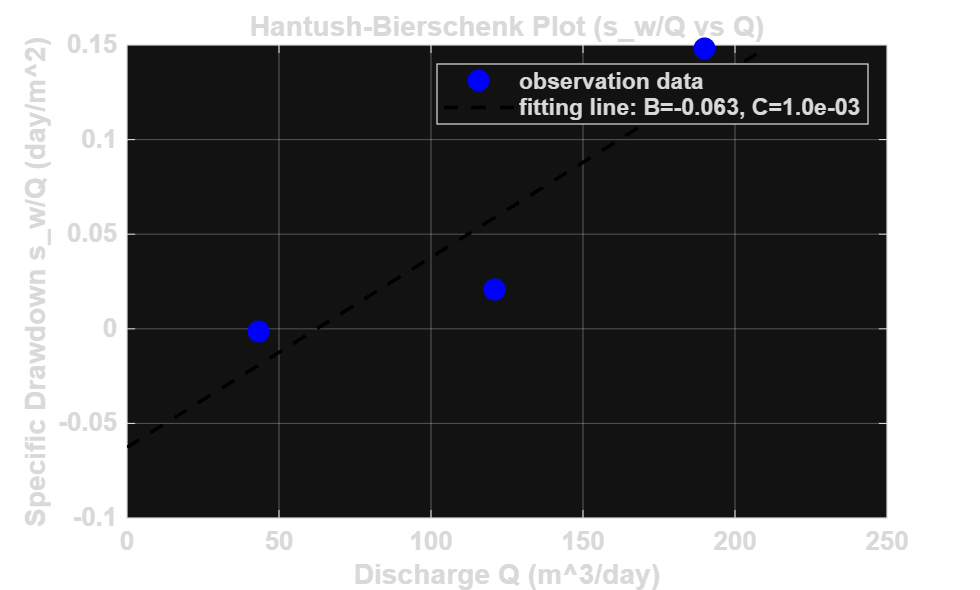

figure('Name', 'Step Test - Well Parameters', 'Color', 'w');
plot(Q_steps, sw_Q, 'bo', 'MarkerFaceColor', 'b', 'MarkerSize', 8); hold on;
q_line = linspace(0, max(Q_steps)*1.1, 100);
plot(q_line, B + C*q_line, 'k--', 'LineWidth', 1.5);
xlabel('Discharge Q (m^3/day)');
ylabel('Specific Drawdown s_w/Q (day/m^2)');
title('Hantush-Bierschenk Plot (s_w/Q vs Q)');
grid on; legend('observation data', ['fitting line: B=' num2str(B,'%.3f') ', C=' num2str(C,'%.1e')]);


% Ew = (B * Q) / (B * Q + C * Q^2) * 100%
Ew = (B .* Q_steps) ./ (B .* Q_steps + C .* Q_steps.^2) * 100;
fprintf('\nWell efficiency\n');


Well efficiency


for i = 1:num_steps
    fprintf('step %d (Q=%.2f L/s): Ew = %.2f%%\n', i, Q_steps_Ls(i), Ew(i));
end

step 1 (Q=0.50 L/s): Ew = 325.11%
step 2 (Q=1.40 L/s): Ew = -106.52%
step 3 (Q=2.20 L/s): Ew = -48.86%


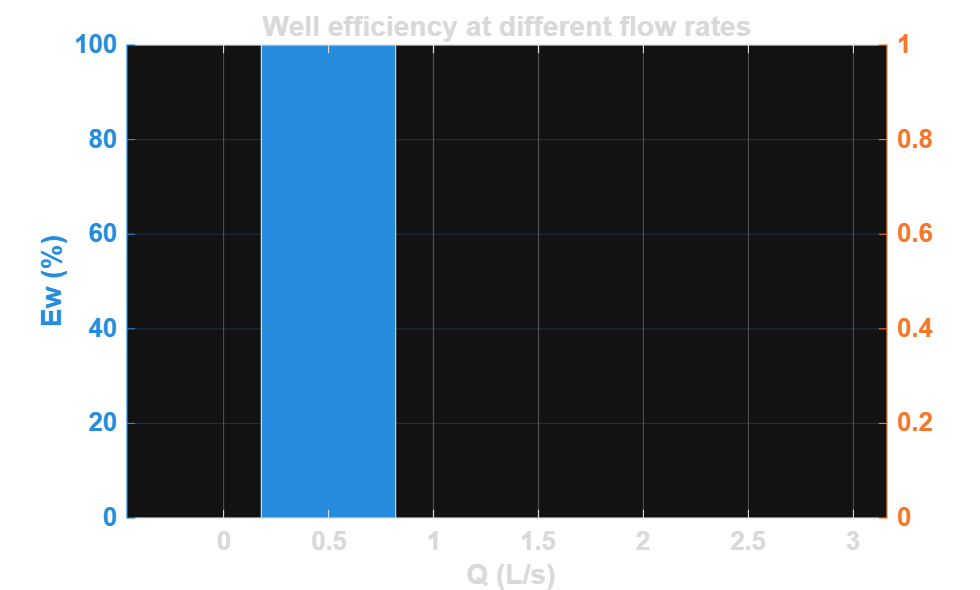


figure('Name', 'Well Efficiency', 'Color', 'w');
yyaxis left
bar(Q_steps_Ls, Ew);
xlabel(' Q (L/s)'); ylabel('Ew (%)');
ylim([0 100]);
title('Well efficiency at different flow rates'); grid on;

*The negative B value and efficiency >100% indicate that well development was occurring during the test (skin factor decreasing).*

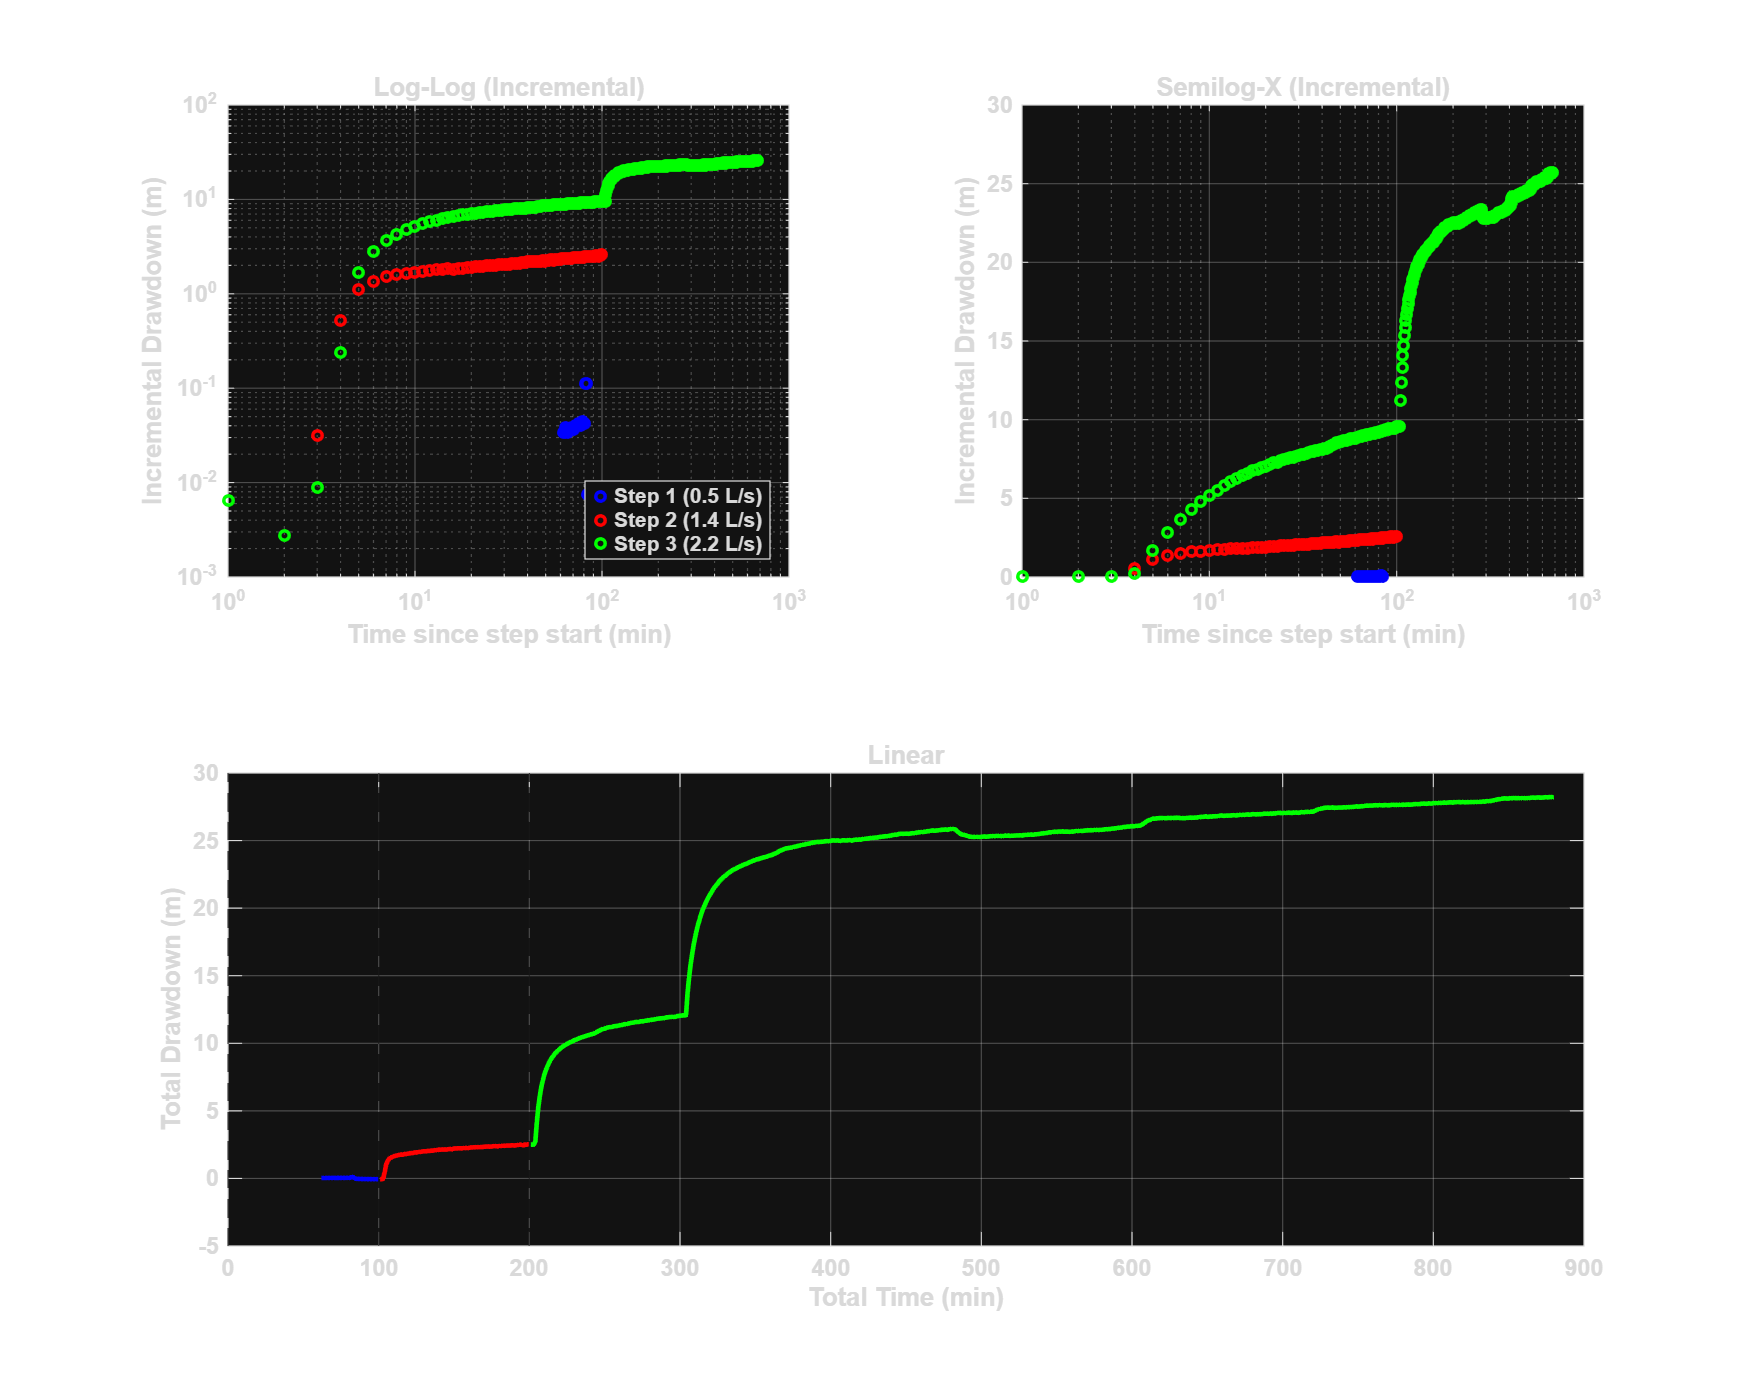


figure('Name', 'Step Evolution Analysis', 'Color', 'w', 'Position', [50 50 1000 800]);
tiledlayout(2, 2);
colors = {'b', 'r', 'g'};
current_start_time = 0;
previous_s_end = 0;
for i = 1:num_steps
    idx = step_indices{i};
    t_seg = t_total(idx);
    s_seg = s_total(idx);
    
    if isempty(t_seg), continue; end
   
    dt = t_seg - current_start_time;
    ds = s_seg - previous_s_end;
    valid = dt > 0 & ds > 0;
    
    nexttile(1);%loglog
    loglog(dt(valid), ds(valid), 'o', 'Color', colors{i}, 'MarkerSize', 4, ...
        'DisplayName', sprintf('Step %d (%.1f L/s)', i, Q_steps_Ls(i))); 
    hold on;
    xlabel('Time since step start (min)'); ylabel('Incremental Drawdown (m)');
    title('Log-Log (Incremental)'); grid on; legend('Location','SouthEast');

    nexttile(2);%semilog
    semilogx(dt(valid), ds(valid), 'o', 'Color', colors{i}, 'MarkerSize', 4); hold on;
    xlabel('Time since step start (min)'); ylabel('Incremental Drawdown (m)');
    title('Semilog-X (Incremental)'); grid on;
    
    nexttile(3, [1 2]); 
    plot(t_seg, s_seg, '-', 'Color', colors{i}, 'LineWidth', 2); hold on;
    xline(current_start_time, '--k');
    
    current_start_time = current_start_time + Durations(i);
    previous_s_end = s_end(i);
end

nexttile(3);
xlabel('Total Time (min)'); ylabel('Total Drawdown (m)');
title('Linear'); grid on;

## Exercise 4 Pumping tests at Puerto Wilches

### pumping, recovery and step-drawdown tests with a well and mirror piezometers, supported by the geophysical and hydrogeological context.

**Configuration and Data**

**Location of the Pumping Well:**

The hydrogeological study is located in **Puerto Wilches, Colombia**, specifically within the area of the **Yariri Wetland (Humedal Yarirí)**. The site lies geographically between the Magdalena River and the "La Independencia" sector.

**Layout of Mirror Piezometers (Distances and Depths):**

The site configuration consists of deep wells targeting a semi-confined to confined aquifer system characterized by alternating layers of silty clays and gravels/sands.

**Well Identification & Stratigraphy:**

- **PZ-1:** A deep well with a total depth of **324 meters**. The lithological log indicates major screened intervals (intake zones) within the deep gravel and sand formations, approximately between **168 m and 266 m**.

- **PZ-2:** A mirror well with a total depth of **277 meters**, screened similarly in the deep aquifer zone (approx. **174 m to 269 m**).

**Radial Distances (***r***):**

- According to the satellite site map, the physical distance between well PZ-1 and PZ-2 is **78 m**.

- * For calculation:* The specific dataset provided for the pumping test analysis records data from an observation point located at a radial distance of r=67.1 m from the pumping well.

**Discharges and Durations of the Tests:**

- **Discharge Rate (***Q***):** The constant discharge rate maintained during the pumping phase was **22.23 l/s** (0.02223 m3/s).

**Duration:**

- **Pumping Phase:** The active pumping period lasted for approximately **5,760 minutes (4 days)**, as indicated by the stabilization and subsequent drop in the provided drawdown curve.

- **Recovery Phase:** A recovery test was initiated immediately after pump shut-off (at t≈5800 min), monitoring the residual drawdown as water levels returned toward static conditions.

- **Static Water Level:** The initial depth to water was recorded at **7.89 meters**.

%clear; clc; close all;
filename_pump = 'pumping_data.txt';    
filename_rec  = 'recovery_data.txt';  
Q_ls = 22.23;        
r = 67.1;            
tp_min = 5760;        
Q = (Q_ls / 1000) * 86400;  % m^3/d
tp_days = tp_min / 1440;    

fprintf('Flow rate (Q): %.2f m^3/d\n', Q);

Flow rate (Q): 1920.67 m^3/d


fprintf('Pumping time:  %.4f d\n', tp_days);

Pumping time:  4.0000 d


data_p = load(filename_pump);
data_p = data_p(data_p(:,1)>0 & data_p(:,2)>0, :); 
t_raw_min = data_p(:,1);  
s_obs = data_p(:,2);          
t_days = t_raw_min / 1440; 

%% 2. Pumping Test Analysis

der = zeros(size(s_obs)); %derivative 
log_t = log(t_days); 
for i = 2:length(s_obs)-1
    der(i) = (s_obs(i+1) - s_obs(i-1)) / (log_t(i+1) - log_t(i-1));
end
der(1)=der(2); der(end)=der(end-1);

% --- B. Cooper-Jacob Method (Linear Fit on Semi-log) ---
% Use last 60% of data
start_idx = floor(length(t_days) * 0.4); 
if start_idx == 0, start_idx = 1; end
p_coeffs = polyfit(log10(t_days(start_idx:end)), s_obs(start_idx:end), 1);
slope = p_coeffs(1);     
intercept = p_coeffs(2); 

T_cj = (2.303 * Q) / (4 * pi * slope);  
t0_days = 10^(-intercept / slope);      
S_cj = (2.25 * T_cj * t0_days) / (r^2); 

theis_func = @(p, t) (Q / (4 * pi * p(1))) * expint((r^2 * p(2)) ./ (4 * p(1) * t)); %thies
obj_fun = @(p) sum((s_obs - theis_func(p, t_days)).^2); %SSR
p_init = [T_cj, S_cj]; 
options = optimset('Display', 'off');
p_best = fminsearch(obj_fun, p_init, options);
T_theis = p_best(1);
S_theis = p_best(2);

s_theis_fit = theis_func(p_best, t_days);
s_cj_fit = p_coeffs(1)*log10(t_days) + p_coeffs(2);

fprintf('puming test result\n');

puming test result


fprintf('%-15s %-15s %-15s\n', 'Method', 'T (m^2/d)', 'S (-)');

Method          T (m^2/d)       S (-)          


fprintf('%-15s %-15.2f %-15.2e\n', 'Cooper-Jacob', T_cj, S_cj);

Cooper-Jacob    1017.15         1.94e-05       


fprintf('%-15s %-15.2f %-15.2e\n', 'Theis', T_theis, S_theis);

Theis           667.03          5.78e-04       


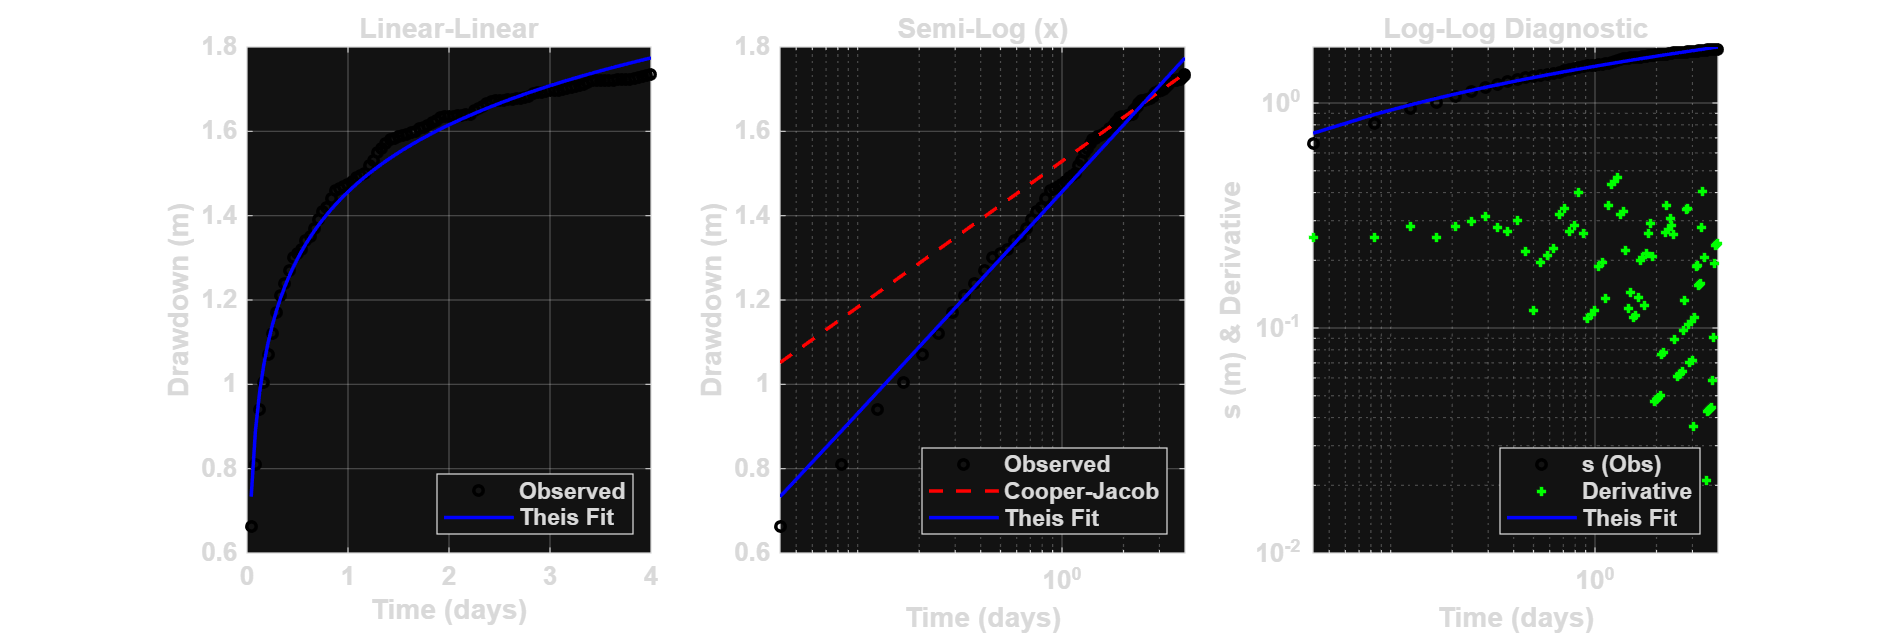

fprintf('\n');

figure('Name', 'Pumping Test: Dimensional', 'Color', 'w', 'Position', [100, 100, 1200, 400]);
subplot(1,3,1);%linear
plot(t_days, s_obs, 'ko', 'MarkerSize', 4); hold on;
plot(t_days, s_theis_fit, 'b-', 'LineWidth', 1.5);
xlabel('Time (days)'); ylabel('Drawdown (m)');
title('Linear-Linear'); grid on;
legend('Observed', 'Theis Fit', 'Location', 'SouthEast');

subplot(1,3,2);%semi-log
semilogx(t_days, s_obs, 'ko', 'MarkerSize', 4); hold on;
semilogx(t_days, s_cj_fit, 'r--', 'LineWidth', 1.5);
semilogx(t_days, s_theis_fit, 'b-', 'LineWidth', 1.5);
xlabel('Time (days)'); ylabel('Drawdown (m)');
title('Semi-Log (x)'); grid on;
legend('Observed', 'Cooper-Jacob', 'Theis Fit', 'Location', 'SouthEast');


subplot(1,3,3);%loglog
loglog(t_days, s_obs, 'ko', 'MarkerSize', 4); hold on;
loglog(t_days, der, 'g+', 'MarkerSize', 4); % Derivative
loglog(t_days, s_theis_fit, 'b-', 'LineWidth', 1.5);
xlabel('Time (days)'); ylabel('s (m) & Derivative');
title('Log-Log Diagnostic'); grid on;
legend('s (Obs)', 'Derivative', 'Theis Fit', 'Location', 'SouthEast');

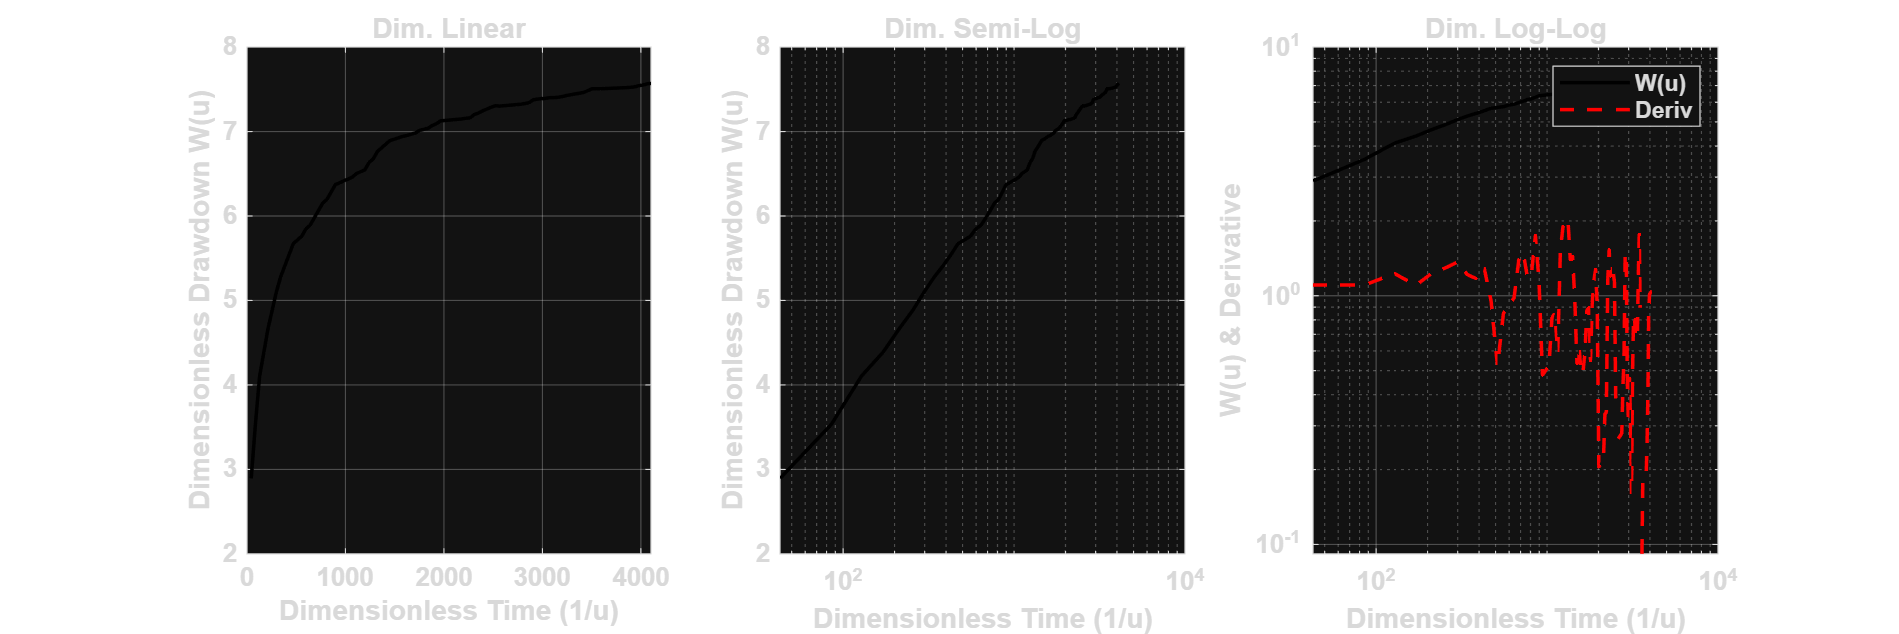


u = (r^2 * S_theis) ./ (4 * T_theis * t_days); %dimensionless
t_dim = 1 ./ u;  
s_dim = (4 * pi * T_theis * s_obs) / Q;
der_dim = (4 * pi * T_theis * der) / Q;

figure('Name', 'Pumping Test: Dimensionless', 'Color', 'w', 'Position', [100, 550, 1200, 400]);


subplot(1,3,1);% linear
plot(t_dim, s_dim, 'k-', 'LineWidth', 1.5);
xlabel('Dimensionless Time (1/u)'); ylabel('Dimensionless Drawdown W(u)');
title('Dim. Linear'); grid on;

subplot(1,3,2);%semilog
semilogx(t_dim, s_dim, 'k-', 'LineWidth', 1.5);
xlabel('Dimensionless Time (1/u)'); ylabel('Dimensionless Drawdown W(u)');
title('Dim. Semi-Log'); grid on;

subplot(1,3,3);%loglog
loglog(t_dim, s_dim, 'k-', 'LineWidth', 1.5); hold on;
loglog(t_dim, der_dim, 'r--', 'LineWidth', 1.5);
xlabel('Dimensionless Time (1/u)'); ylabel('W(u) & Derivative');
title('Dim. Log-Log'); grid on; legend('W(u)', 'Deriv');

revovery test result


Method          T (m^2/d)       S (-)          


C-J Recovery    594.92          N/A            


Theis (Auto)    668.83          -7.61e-03      


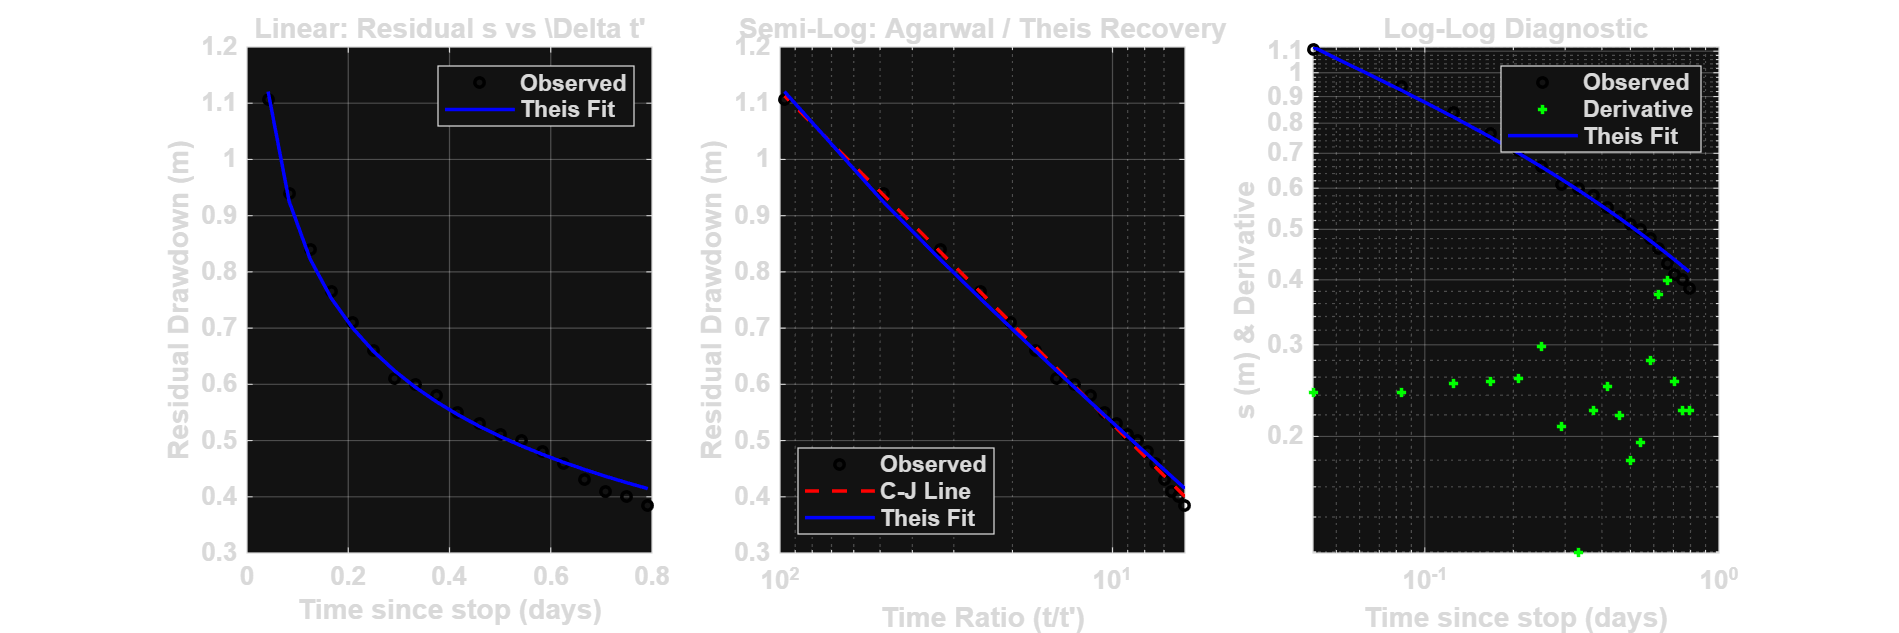

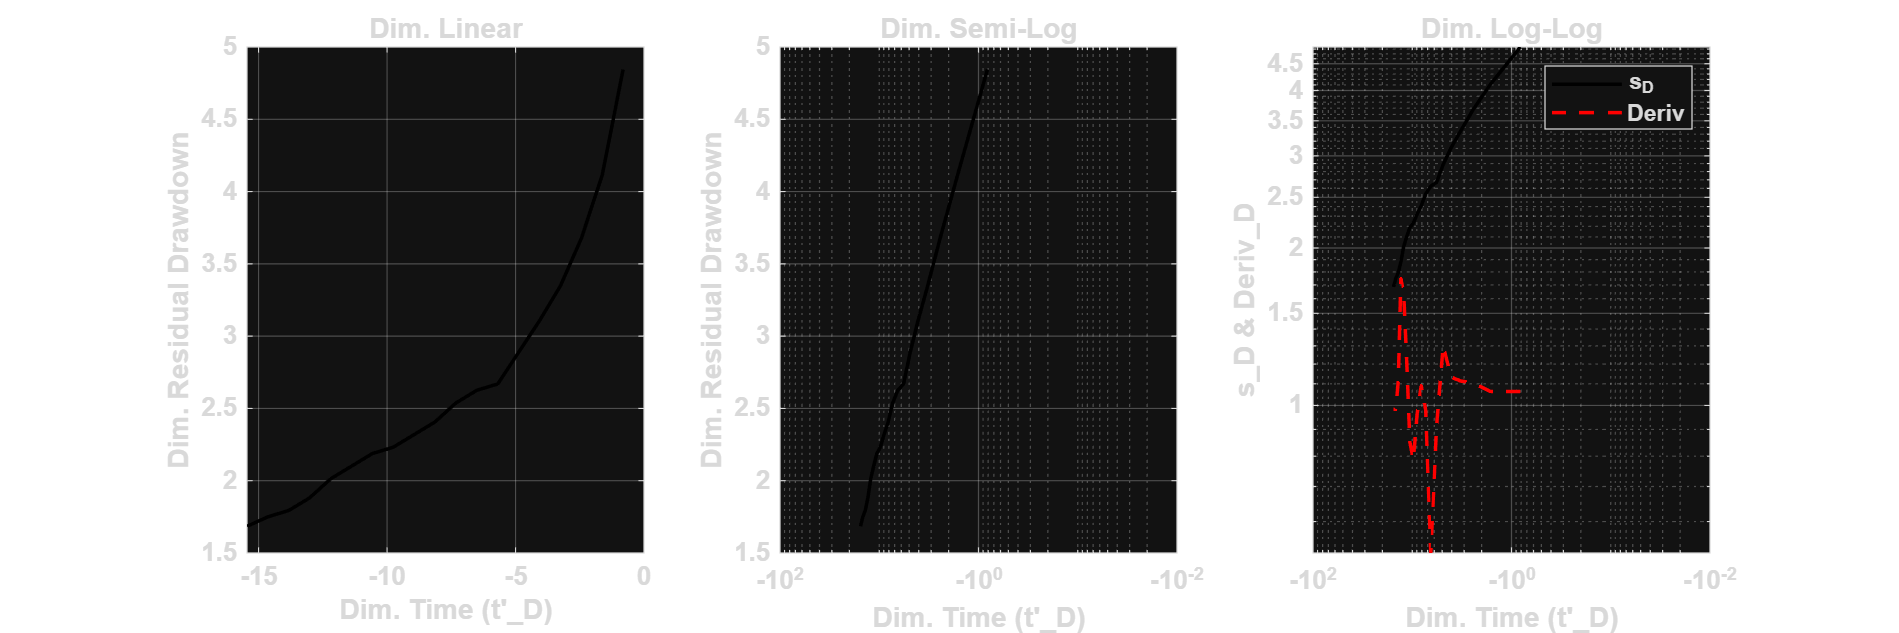


% Recovery test
if exist(filename_rec, 'file')
    data_r = load(filename_rec);
    data_r = data_r(data_r(:,1)>0 & data_r(:,2)>0, :); 
    dt_min = data_r(:,1); 
    s_res_obs = data_r(:,2);  % residual drawdown
    
    dt_days = dt_min / 1440;
    
  
    der_rec = zeros(size(s_res_obs));%derivative
    log_dt = log(dt_days);
    for i = 2:length(s_res_obs)-1
        der_rec(i) = abs((s_res_obs(i+1) - s_res_obs(i-1)) / (log_dt(i+1) - log_dt(i-1)));
    end
    der_rec(1)=der_rec(2); der_rec(end)=der_rec(end-1);

   
    time_ratio = (tp_days + dt_days) ./ dt_days;%CJ
    idx_rec = find(time_ratio < 100 & time_ratio > 1.5); 
    if isempty(idx_rec), idx_rec = 1:length(time_ratio); end
    p_rec = polyfit(log10(time_ratio(idx_rec)), s_res_obs(idx_rec), 1);
    
    T_rec_cj = (2.303 * Q) / (4 * pi * abs(p_rec(1)));
  %thies revovery
    theis_rec_func = @(p, dt) (Q / (4*pi*p(1))) * ...
        (expint((r^2*p(2))./(4*p(1)*(tp_days+dt))) - expint((r^2*p(2))./(4*p(1)*dt)));
    obj_rec = @(p) sum((s_res_obs - theis_rec_func(p, dt_days)).^2); 
    p_rec_best = fminsearch(obj_rec, [T_theis, S_theis], options);
    T_rec_theis = p_rec_best(1);
    S_rec_theis = p_rec_best(2);
    s_rec_fit = theis_rec_func(p_rec_best, dt_days);

    fprintf('revovery test result\n');
    fprintf('%-15s %-15s %-15s\n', 'Method', 'T (m^2/d)', 'S (-)');
    fprintf('%-15s %-15.2f %-15s\n', 'C-J Recovery', T_rec_cj, 'N/A');
    fprintf('%-15s %-15.2f %-15.2e\n', 'Theis (Auto)', T_rec_theis, S_rec_theis);

 
    figure('Name', 'Recovery Test: Dimensional', 'Color', 'w', 'Position', [150, 150, 1200, 400]);

    subplot(1,3,1);%linear
    plot(dt_days, s_res_obs, 'ko', 'MarkerSize', 4); hold on;
    plot(dt_days, s_rec_fit, 'b-', 'LineWidth', 1.5);
    xlabel('Time since stop (days)'); ylabel('Residual Drawdown (m)');
    title('Linear: Residual s vs \Delta t'''); grid on;
    legend('Observed', 'Theis Fit');

    subplot(1,3,2);%semilog
    semilogx(time_ratio, s_res_obs, 'ko', 'MarkerSize', 4); hold on;
    % Plot C-J line
    x_fit = linspace(min(time_ratio), max(time_ratio), 100);
    y_fit = polyval(p_rec, log10(x_fit));
    semilogx(x_fit, y_fit, 'r--', 'LineWidth', 1.5);
    % Plot theis fit
    semilogx(time_ratio, s_rec_fit, 'b-', 'LineWidth', 1.5);
    set(gca, 'XDir', 'reverse'); 
    xlabel('Time Ratio (t/t'')'); ylabel('Residual Drawdown (m)');
    title('Semi-Log: Agarwal / Theis Recovery'); grid on;
    legend('Observed', 'C-J Line', 'Theis Fit', 'Location', 'SouthWest');

    subplot(1,3,3);%loglog
    loglog(dt_days, s_res_obs, 'ko', 'MarkerSize', 4); hold on;
    loglog(dt_days, der_rec, 'g+', 'MarkerSize', 4); 
    loglog(dt_days, s_rec_fit, 'b-', 'LineWidth', 1.5);
    xlabel('Time since stop (days)'); ylabel('s (m) & Derivative');
    title('Log-Log Diagnostic'); grid on;
    legend('Observed', 'Derivative', 'Theis Fit');

    % s_D = (4piT * s) / Q
    % t_D = (T * t') / (r^2 * S)
    
    s_rec_dim = (4 * pi * T_rec_theis * s_res_obs) / Q;
    t_rec_dim = (T_rec_theis * dt_days) / (r^2 * S_rec_theis);
    der_rec_dim = (4 * pi * T_rec_theis * der_rec) / Q;

    figure('Name', 'Recovery Test: Dimensionless', 'Color', 'w', 'Position', [150, 600, 1200, 400]);

    subplot(1,3,1);%linear
    plot(t_rec_dim, s_rec_dim, 'k-', 'LineWidth', 1.5);
    xlabel('Dim. Time (t''_D)'); ylabel('Dim. Residual Drawdown');
    title('Dim. Linear'); grid on;

    subplot(1,3,2);%semilog
    semilogx(t_rec_dim, s_rec_dim, 'k-', 'LineWidth', 1.5);
    xlabel('Dim. Time (t''_D)'); ylabel('Dim. Residual Drawdown');
    title('Dim. Semi-Log'); grid on;

    subplot(1,3,3);%loglog
    loglog(t_rec_dim, s_rec_dim, 'k-', 'LineWidth', 1.5); hold on;
    loglog(t_rec_dim, der_rec_dim, 'r--', 'LineWidth', 1.5);
    xlabel('Dim. Time (t''_D)'); ylabel('s_D & Deriv_D');
    title('Dim. Log-Log'); grid on; legend('s_D', 'Deriv');

else
    warning('Recovery data file not found.');
end

## Conclusion

**1. Variation of T and S parameters and physical meaning**

The four scenarios represent vastly different hydrogeological environments, ranging from low-permeability formations to highly conductive gravel aquifers.

**    Transmissivity (***T***) comparison:**

- **Exercise 3 (UNAL):** Lowest Transmissivity (T≈8.7m²/d). This indicates a formation with **low hydraulic conductivity**, likely composed of finer materials like silts or fine sands with higher resistance to flow.

- **Exercise 1 (Fetter example):** Moderate Transmissivity (T=123m²/d). Represents a textbook **standard aquifer** with good permeability.

- **Exercise 2 (Two piezometers):** High Transmissivity (T= 480−500m²/d). Indicates a **productive aquifer**. The consistency between P30 and P90 (4.2% difference) confirms the aquifer is homogeneous over the tested distance.

- **Exercise 4 (Puerto Wilches):** Highest Transmissivity (T=667 m²/d via Theis). The site description confirms this is a deep well screened in **gravels and sands**, which physically explains the high capacity to transmit water.

**    Storativity (S) comparison:**

- **Exercises 1, 2, and 4:** All resulted in *S* values in the range of 10−4 to 10−5. Physically, this confirms these are **confined aquifers**, where water is released via the elastic expansion of water and compression of the rock matrix, rather than draining pores.

- **Exercise 3:** The automated fitting resulted in a significantly higher S (1.3×10−1), though the fit was imperfect. Physically, this value suggests **unconfined or semi-confined conditions**, or potentially significant leakage, distinguishing it from the deep confined systems in the other exercises.

**2. Well efficiency and well parameters (Exercise 3)**

- **Turbulent flow (**C**):** The calculated C was 1.00×10−3 d²/m⁵, confirming that at higher pumping rates, turbulent flow occurs within the wellbore or screen filter.

- **Linear loss (**B**) and efficiency:**The analysis produced a **negative** B **value** (−0.0626 d/m²) and **efficiencies > 100% **

- **Physical Meaning:** Theoretically, B (laminar aquifer loss) cannot be negative. A negative B and increasing efficiency during a step test typically indicate that the **well is being "developed" during the test**. As the pumping rate increased, fine particles were likely cleared from the well screen, reducing the skin effect and effectively improving the well's performance in real-time.

**3. Role of Diagnostic Curves**

The derivative plots (Log-Log diagnostic) played distinct roles in each scenario:

- **Identifying radial flow (All exercises):** In all cases, the stabilization of the derivative curve to a horizontal line confirmed the establishment of **Infinite Acting Radial Flow (IARF)**. This validated the use of Theis-based solutions.

- **Identifying start times (Exercise 1):** The diagnostic plot revealed that radial flow appeared visually stable around 30-40 minutes. However, the theoretical Cooper-Jacob criterion (u<0.01) required waiting until 386 minutes. The diagnostic plot allowed for a more pragmatic engineering decision to use data from 30 minutes onwards.

- **Recognizing well effects (Exercise 1 & 4): **

- In Exercise 1, the lack of a "unit slope" (slope = 1) at early times confirmed **no wellbore storage effects** were influencing the piezometer data. This is physically consistent with the observation wells being far from the pumping well (r=251and r=67).

- **Boundary effects (Exercise 4):** Despite the complexity of the Puerto Wilches site, the derivative curve remained generally horizontal in late time, showing no upward trend (barrier) or downward drop (recharge). This confirmed the aquifer acts as an **infinite system** within the 4-day test duration.

**4. Suitability of Theis model vs. Cooper-Jacob Approximation**

- **Consistency (Exercise 1 & 2):** In idealized or homogeneous scenarios, both methods produced nearly identical results. For example, in Exercise 2, the variance was negligible. Here, Cooper-Jacob is a suitable and simpler alternative.

- **Discrepancy and Reliability (Exercise 4): **In the complex Puerto Wilches pumping test, there was a significant discrepancy: **Cooper-Jacob:** *T*≈1017 m²/d, but **Theis (Auto):** T≈667 m²/d; however, the **Recovery test**  resulted in:T≈668m/d

- **Evaluation:** The Pumping Theis result (667) matches the Recovery Theis result (668) almost perfectly. The Cooper-Jacob pumping result (1017) was an outlier.

- **Conclusion:** This demonstrates that **Theis (via automatic fitting) is more robust and reliable** in complex, real-world scenarios where the strict time/u-value criteria for the Cooper-Jacob approximation might not be fully met, leading to overestimation of Transmissivity by the linear approximation method.

## Discussion

**1. Diagnostic plots are important for aquifer analysis**

- **Knowledge:** Plotting both drawdown (*s*) and the derivative (*d**s*/*d*(ln*t*)) on a log-log scale is essential.

- **Insight:** Relying solely on the drawdown curve makes it difficult to characterize the aquifer. The derivative curve clearly reveals the flow regime:

- **Horizontal line:** Indicates Infinite Acting Radial Flow (IARF), a prerequisite for using Theis/Cooper-Jacob solutions.

- **Unit slope (Slope = 1):** Indicates early-time wellbore storage effects (important theoretically, though not observed in Exercise 1).

- **Upward/Downward Trends:** Indicate boundary effects (impermeable barriers or recharge boundaries).

- **Key lesson (Ex 1 & 4):** Calculated T and S values are only reliable once the derivative curve has stabilized.

**2. Cross-validation of methods (Theis vs. Cooper-Jacob vs. Recovery)**

- **Theis (Auto-fitting):** Most versatile; utilizes the entire dataset.

- **Cooper-Jacob (Straight line):** Simple to calculate but strictly limited by time/u-value (u<0.01).

- **Recovery test:** Unaffected by pumping turbulence, often considered the most reliable source for Transmissivity (T).

- **Key lesson (Ex 4):** When the Cooper-Jacob estimate (*T*≈1017) diverged significantly from the Theis estimate (*T*≈667), the **Recovery test result (**668**)** served as the definitive validation. This proved the accuracy of the Theis solution and highlighted the potential errors of Cooper-Jacob when early-time data is included.

**3. Real-world imperfections (the negative** B v**alue in exercise 3)**

- **Knowledge:** Step-drawdown tests are used to separate aquifer loss (*B*) from well loss (*C*).

- **Insight:** Theoretically, *B* must be positive. However, Exercise 3 yielded a negative value and a well efficiency >100%. This teaches us that **"Data doesn't lie, but environments change."**

- **Interpretation:** The well was likely undergoing **"Well development"** during the test (cleaning of fines from the screen), causing permeability to improve in real-time. Understanding the physical context is more important than rote memorization of formulas.